data=readmatrix('data.csv')';
x=data(2:4,:);
y=data(5:8,:);
m=length(y);

for i=1:3
    x1(i,:)=(x(i,:)-min(x(i,:)))/(max(x(i,:))-min(x(i,:)));
end

hiddenLayerSize=10;
net = fitnet(hiddenLayerSize);
net.divideParam.trainRatio=60/100;
net.divideParam.valRatio=30/100;
net.divideParam.testRatio=10/100;
[net,tr]=train(net, x1,y);

yTrain=net(x1(:,tr.trainInd));
yTrainTrue=y(:,tr.trainInd);
sqrt(mean((yTrain-yTrainTrue).^2))

ans =     0.0360    0.0359    0.0367    0.0384    0.0397    0.0397    0.0397    0.0397    0.0400    0.0403    0.0408    0.0409    0.0407    0.0402    0.0398    0.0390    0.0380    0.0375    0.0375    0.0365    0.0354    0.0318    0.0294    0.0329    0.0339    0.0346    0.0352    0.0341    0.0335    0.0349    0.0351    0.0351    0.0347    0.0337    0.0296    0.0262    0.0268    0.0282    0.0299    0.0314    0.0328    0.0336    0.0342    0.0343    0.6753    0.6749    0.6747    0.6747    0.6747    0.6747


yVal=net(x1(:,tr.valInd));
yValTrue=y(:,tr.valInd);
sqrt(mean((yVal-yValTrue).^2))

ans =     0.0363    0.0409    0.0405    0.0329    0.0299    0.0303    0.0346    0.0307    0.0302    0.0304    0.0351    0.0322    0.0276    0.0264    0.0327    0.0328    0.0340    0.6747    0.6747    0.6747    0.6747    0.6747    0.6746    0.6727    0.6726    0.6702    0.6648    0.1852    0.2234    0.2415    0.2607    0.3868    0.3990    0.4056    0.4103    0.4198    0.4245    0.4239    0.3737    0.3561    0.3475    0.3369    0.2961    0.2807    0.2416    0.2131    0.4226    0.6924    0.6924    0.6925


yTest=net(x1(:,tr.testInd));
yTestTrue=y(:,tr.testInd);
sqrt(mean((yTest-yTestTrue).^2))

ans =     0.0406    0.0339    0.0306    0.0295    0.0292    0.0319    0.0319    0.0313    0.6727    0.3030    0.1805    0.2343    0.2335    0.3246    0.5015    0.6599    0.6813    0.6625    0.3502    0.2085    0.2348    0.2448    0.2394    0.6933    0.6932    0.6790    0.6790    0.2123    0.2835    0.2757    0.2707    0.4246    0.2725    0.2722    0.2458    0.2200    0.2159    0.1864    0.1935    0.5890    0.1695    0.1704    0.2286    0.0531    0.0993    0.1053    0.4305    0.5014    0.3754    0.0240


for i=1:60
    hiddenLayerSize=i;
net = fitnet(hiddenLayerSize);
net.divideParam.trainRatio=60/100;
net.divideParam.valRatio=30/100;
net.divideParam.testRatio=10/100;

%determine the error of ann
[net,tr]=train(net, x1,y);
yTrain=net(x1(:,tr.trainInd));
yTrainTrue=y(:,tr.trainInd);
rmse_train=sqrt(mean((yTrain-yTrainTrue).^2))
t(i)=min(rmse_train);
yVal=net(x1(:,tr.valInd));
yValTrue=y(:,tr.valInd);
rmse_val=sqrt(mean((yVal-yValTrue).^2))
v(i)=min(rmse_val);
yTest=net(x1(:,tr.testInd));
yTestTrue=y(:,tr.testInd);
rmse_test=sqrt(mean((yTest-yTestTrue).^2))
w(i)=min(rmse_test);
end

rmse_train =     0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1702    0.1704    0.1706    0.1711    0.1735    0.1754    0.1775    0.1792    0.1807    0.1822    0.1843    0.1866    0.1871    0.1867    0.1843    0.1826    0.1826    0.1809    0.1792    0.6228    0.6235    0.6238    0.6238    0.6238    0.6239    0.6239


rmse_val =     0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1701    0.1702    0.1702    0.1708    0.1716    0.1760    0.1760    0.1856    0.1871    0.1857    0.1827    0.1777    0.1762    0.6248    0.6254    0.6253    0.6252    0.5274    0.5451    0.5482    0.5490    0.5490    0.5490    0.5490    0.5490    0.5490    0.5490    0.5490    0.5490    0.5472    0.6207    0.6208    0.6219    0.6260    0.6261    0.6261    0.6261    0.6261    0.6261    0.6261    0.6261    0.6261    0.6260


rmse_test =     0.1701    0.1701    0.1701    0.1701    0.1701    0.1721    0.6244    0.5851    0.5488    0.5490    0.5490    0.5490    0.5490    0.5490    0.5490    0.6261    0.6261    0.6260    0.6260    0.5490    0.5490    0.5716    0.6220    0.6246    0.6261    0.6261    0.6261    0.5490    0.5490    0.5490    0.5283    0.6261    0.6261    0.5485    0.5485    0.6261    0.5106    0.1856    0.1703    0.1701    0.1701    0.1701    0.1714    0.1701    0.1781    0.4187    0.1705    0.2225    0.1701    0.1701


rmse_train =     0.0899    0.0901    0.0821    0.0820    0.0820    0.0754    0.0696    0.0666    0.0608    0.0567    0.0528    0.0461    0.0426    0.0413    0.0413    0.0398    0.0385    0.0372    0.0365    0.0356    0.0355    0.0355    0.0357    0.0363    0.0386    0.0398    0.0417    0.0441    0.0441    0.0710    0.0744    0.0791    0.0822    0.0836    0.0828    0.0809    0.0786    0.0761    0.0734    0.0652    0.0628    0.0608    0.0594    0.0582    0.0583    0.6606    0.6606    0.6606    0.6606    0.6606


rmse_val =     0.0890    0.0860    0.0821    0.0725    0.0637    0.0488    0.0543    0.0600    0.0637    0.0674    0.0827    0.0827    0.0706    0.0678    0.0609    0.0608    0.6606    0.6604    0.6565    0.6560    0.6553    0.6486    0.5552    0.5499    0.5457    0.5455    0.5692    0.5796    0.5826    0.5847    0.5871    0.5896    0.6083    0.6116    0.6253    0.6291    0.5825    0.5494    0.5674    0.6201    0.6588    0.6588    0.6588    0.6590    0.6597    0.6798    0.6800    0.6789    0.6675    0.6541


rmse_test =     0.0902    0.0806    0.0791    0.0360    0.0373    0.0839    0.0836    0.0585    0.6618    0.6611    0.6606    0.6454    0.6355    0.6168    0.5607    0.6064    0.6163    0.5555    0.6550    0.6639    0.6541    0.6549    0.6482    0.5537    0.5848    0.5834    0.5800    0.6044    0.6330    0.6511    0.6511    0.6854    0.6470    0.6084    0.5518    0.6503    0.6323    0.0416    0.0397    0.0801    0.0669    0.0821    0.0447    0.0436    0.0405    0.0451    0.0527    0.0787    0.0540    0.0867


rmse_train =     0.0971    0.0988    0.1035    0.1041    0.1026    0.0976    0.0920    0.0888    0.0854    0.0819    0.0766    0.0712    0.0613    0.0556    0.0510    0.0486    0.0434    0.0423    0.0412    0.0407    0.0404    0.0407    0.0419    0.0432    0.0544    0.0608    0.0642    0.0674    0.0724    0.0761    0.0769    0.0769    0.0792    0.0794    0.0792    0.0726    0.0632    0.0612    0.0593    0.0562    0.6569    0.6568    0.6568    0.6568    0.6568    0.6568    0.6568    0.6566    0.6563    0.6544


rmse_val =     0.1013    0.1026    0.1025    0.1016    0.1006    0.0535    0.0535    0.0460    0.0446    0.0417    0.0404    0.0411    0.0432    0.0499    0.0575    0.0782    0.0766    0.0747    0.0679    0.0655    0.0611    0.0611    0.0579    0.6568    0.6568    0.6568    0.6568    0.6558    0.6548    0.6540    0.6531    0.6523    0.6034    0.5305    0.4169    0.4141    0.4151    0.4175    0.4239    0.4673    0.4834    0.4992    0.5087    0.5153    0.5206    0.5377    0.5310    0.4656    0.4437    0.4210


rmse_test =     0.1025    0.0950    0.0461    0.0782    0.0703    0.0569    0.6569    0.6539    0.6469    0.4085    0.4343    0.4902    0.4581    0.6478    0.4446    0.4360    0.4213    0.6545    0.6731    0.6629    0.6423    0.4230    0.6526    0.6530    0.6703    0.6708    0.6462    0.6399    0.4178    0.4193    0.5610    0.4483    0.1356    0.1195    0.0575    0.0539    0.0582    0.0473    0.0389    0.0377    0.0369    0.2776    0.0517    0.0483    0.0494    0.1175    0.0972    0.0670    0.0542    0.0509


rmse_train =     0.0355    0.0345    0.0333    0.0326    0.0332    0.0343    0.0343    0.0343    0.0343    0.0347    0.0355    0.0357    0.0358    0.0354    0.0349    0.0339    0.0326    0.0300    0.0289    0.0299    0.0326    0.0355    0.0388    0.0468    0.0506    0.0610    0.0702    0.0708    0.0689    0.0645    0.0440    0.0324    0.0219    0.0193    0.0181    0.0190    0.0242    0.0242    0.0277    0.0317    0.0355    0.0395    0.0460    0.0693    0.0748    0.0763    0.0769    0.0766    0.0754    0.0735


rmse_val =     0.0350    0.0357    0.0432    0.0661    0.0645    0.0556    0.0262    0.0228    0.0511    0.0561    0.0610    0.0654    0.0724    0.0763    0.0763    0.6609    0.6609    0.6609    0.6611    0.6615    0.6630    0.6290    0.5175    0.4371    0.4391    0.4391    0.4390    0.4390    0.4390    0.4390    0.4390    0.4390    0.4390    0.4390    0.4390    0.4390    0.4388    0.5146    0.6833    0.6834    0.6969    0.5707    0.5744    0.5733    0.5716    0.5794    0.6707    0.6920    0.6919    0.4494


rmse_test =     0.0288    0.0287    0.0287    0.0551    0.6609    0.6623    0.6627    0.6635    0.6612    0.6833    0.6834    0.6864    0.6386    0.5766    0.6914    0.4390    0.4390    0.4390    0.4390    0.6051    0.6092    0.6937    0.6952    0.6923    0.6923    0.4144    0.3973    0.4390    0.4390    0.4389    0.6261    0.6948    0.6921    0.6921    0.4348    0.4388    0.4391    0.4390    0.4390    0.4390    0.5678    0.5779    0.6716    0.4050    0.0208    0.0292    0.3294    0.4448    0.3397    0.0946


rmse_train =     0.0507    0.0561    0.0561    0.0562    0.0562    0.0577    0.0591    0.0628    0.0627    0.0544    0.0425    0.0390    0.0362    0.0357    0.0353    0.0355    0.0364    0.0379    0.0394    0.0404    0.0412    0.0420    0.0425    0.0433    0.0459    0.0492    0.0536    0.0550    0.0550    0.0582    0.0617    0.0646    0.0674    0.0781    0.0790    0.0781    0.0740    0.0740    0.0711    0.0642    0.6549    0.6565    0.6573    0.6573    0.6574    0.6574    0.6574    0.6574    0.6575    0.6584


rmse_val =     0.0403    0.0402    0.0412    0.0445    0.0613    0.0624    0.0619    0.0605    0.0470    0.0409    0.0375    0.0354    0.0353    0.0358    0.0370    0.0384    0.0394    0.0444    0.0716    0.0743    0.0790    0.0765    0.0606    0.6573    0.6576    0.6594    0.6605    0.6628    0.5189    0.3730    0.4407    0.4445    0.4477    0.4465    0.4460    0.4457    0.4447    0.4438    0.4436    0.4432    0.4430    0.4430    0.4429    0.4404    0.4372    0.3856    0.6765    0.6706    0.6712    0.6740


rmse_test =     0.0578    0.0409    0.0389    0.0765    0.0742    0.0677    0.6574    0.6587    0.4917    0.4455    0.4467    0.4429    0.4372    0.4286    0.5081    0.6589    0.6795    0.6788    0.6750    0.3976    0.4430    0.6626    0.6626    0.6626    0.6419    0.6552    0.4430    0.4429    0.4202    0.6961    0.6778    0.6777    0.4231    0.4231    0.4428    0.4413    0.5932    0.6777    0.3557    0.0612    0.1450    0.3488    0.2969    0.1200    0.1945    0.1177    0.0435    0.1994    0.0891    0.2615


rmse_train =     0.0541    0.0610    0.0634    0.0634    0.0638    0.0644    0.0607    0.0586    0.0564    0.0524    0.0503    0.0496    0.0496    0.0479    0.0463    0.0458    0.0456    0.0453    0.0451    0.0448    0.0444    0.0443    0.0443    0.0445    0.0454    0.0472    0.0579    0.0608    0.0676    0.0676    0.0675    0.0666    0.0653    0.0607    0.0589    0.0576    0.0567    0.0562    0.0555    0.0551    0.0551    0.0551    0.0544    0.0525    0.6577    0.6579    0.6579    0.6579    0.6579    0.6579


rmse_val =     0.0544    0.0554    0.0576    0.0633    0.0642    0.0645    0.0639    0.0631    0.0620    0.0486    0.0471    0.0466    0.0445    0.0500    0.0523    0.0650    0.0678    0.0628    0.0558    0.0535    0.0515    0.6573    0.6579    0.6579    0.6579    0.6578    0.6577    0.5462    0.5103    0.4501    0.2016    0.2050    0.2199    0.2297    0.2445    0.3471    0.3948    0.4078    0.4076    0.3950    0.3883    0.3779    0.3685    0.2765    0.6615    0.6615    0.6616    0.6632    0.6649    0.6624


rmse_test =     0.0633    0.0446    0.0550    0.0673    0.6579    0.6579    0.6577    0.6468    0.6344    0.2015    0.2653    0.2733    0.2997    0.3906    0.4005    0.4023    0.3402    0.6665    0.6656    0.5490    0.5012    0.3399    0.2554    0.2456    0.6616    0.6512    0.6617    0.6624    0.2883    0.6618    0.6509    0.6496    0.6449    0.6483    0.2022    0.2764    0.2754    0.2693    0.2482    0.2247    0.2105    0.1971    0.6620    0.6577    0.1995    0.1831    0.0535    0.0644    0.2739    0.0431


rmse_train =     0.0391    0.0371    0.0342    0.0318    0.0313    0.0319    0.0319    0.0319    0.0321    0.0324    0.0330    0.0336    0.0345    0.0373    0.0427    0.0469    0.0552    0.0593    0.0620    0.0601    0.0578    0.0560    0.0541    0.0414    0.0392    0.0346    0.0334    0.0347    0.0380    0.0410    0.0443    0.0479    0.0578    0.0562    0.0543    0.0519    0.0476    0.0443    0.0404    0.0403    0.0410    0.0418    0.0421    0.0421    0.0420    0.6686    0.6680    0.6680    0.6679    0.6679


rmse_val =     0.0319    0.0392    0.0604    0.0619    0.0516    0.0480    0.0446    0.0367    0.0514    0.0560    0.0579    0.0579    0.0575    0.0418    0.0399    0.0421    0.0413    0.0404    0.0396    0.6699    0.6680    0.6678    0.6654    0.6654    0.6624    0.5977    0.2011    0.1826    0.1866    0.1958    0.2192    0.2483    0.2546    0.2777    0.3834    0.3991    0.4039    0.4037    0.3984    0.3633    0.3568    0.3305    0.2236    0.5298    0.6840    0.6887    0.6213    0.5964    0.6614    0.6955


rmse_test =     0.0357    0.0604    0.0614    0.0613    0.0346    0.6679    0.6652    0.6560    0.6458    0.5484    0.3102    0.2853    0.2065    0.6840    0.5734    0.5692    0.6956    0.2542    0.3324    0.2511    0.5458    0.2935    0.2286    0.6789    0.6795    0.3409    0.3395    0.3415    0.3509    0.3977    0.1912    0.2577    0.2642    0.2543    0.6886    0.1856    0.5251    0.4694    0.0490    0.0197    0.1634    0.0674    0.2854    0.0286    0.0214    0.0198    0.1157    0.0163    0.1396    0.0344


rmse_train =     0.0364    0.0397    0.0413    0.0418    0.0418    0.0409    0.0391    0.0379    0.0361    0.0279    0.0267    0.0257    0.0247    0.0241    0.0236    0.0230    0.0231    0.0235    0.0286    0.0312    0.0309    0.0332    0.0360    0.0379    0.0423    0.0455    0.0489    0.0520    0.0545    0.0562    0.0570    0.0570    0.0570    0.0556    0.0516    0.6619    0.6626    0.6631    0.6631    0.6631    0.6631    0.6631    0.6631    0.6632    0.6637    0.6643    0.6651    0.6664    0.6668    0.6677


rmse_val =     0.0368    0.0364    0.0375    0.0413    0.0413    0.0413    0.0416    0.0415    0.0401    0.0342    0.0308    0.0287    0.0245    0.0262    0.0301    0.0316    0.0316    0.0273    0.0227    0.0208    0.0205    0.0219    0.0243    0.0290    0.0325    0.0345    0.0397    0.0539    0.6675    0.6654    0.6345    0.3622    0.1787    0.1741    0.2000    0.2132    0.2380    0.2809    0.3719    0.3934    0.4222    0.4159    0.4030    0.3728    0.3605    0.3523    0.3426    0.3317    0.3194    0.2910


rmse_test =     0.0279    0.0231    0.0332    0.0355    0.0365    0.0568    0.6631    0.6631    0.6632    0.6672    0.2312    0.4259    0.3805    0.2726    0.6917    0.5648    0.5773    0.6907    0.6906    0.1882    0.3282    0.3403    0.3315    0.2392    0.1738    0.2356    0.3853    0.2693    0.2726    0.2868    0.6766    0.1598    0.2229    0.2999    0.2976    0.2954    0.2829    0.2499    0.2403    0.1844    0.3540    0.6935    0.2567    0.2590    0.2691    0.2743    0.2775    0.6877    0.6877    0.6209


rmse_train =     0.0264    0.0255    0.0266    0.0267    0.0267    0.0271    0.0276    0.0330    0.0416    0.0545    0.0582    0.0592    0.0598    0.0593    0.0566    0.0518    0.0468    0.0430    0.0337    0.0313    0.0297    0.0297    0.0299    0.0333    0.0431    0.0477    0.0522    0.0564    0.0617    0.0612    0.0588    0.0502    0.0455    0.0415    0.0368    0.0369    0.0358    0.6779    0.6764    0.6757    0.6757    0.6757    0.6755    0.6755    0.6755    0.6755    0.6755    0.6754    0.6746    0.6737


rmse_val =     0.0334    0.0266    0.0287    0.0313    0.0351    0.0592    0.0599    0.0582    0.0359    0.0635    0.0635    0.0557    0.0386    0.0362    0.0363    0.0367    0.0369    0.0369    0.0347    0.6755    0.6719    0.6686    0.6064    0.5600    0.5024    0.3229    0.1707    0.3063    0.3142    0.3238    0.3557    0.3745    0.3879    0.4060    0.3824    0.3738    0.3564    0.6913    0.6913    0.6913    0.6937    0.6966    0.6041    0.5753    0.7010    0.5672    0.4425    0.1692    0.1907    0.2054


rmse_test =     0.0359    0.0297    0.0299    0.0375    0.0461    0.0539    0.0496    0.0393    0.0389    0.0635    0.0628    0.0366    0.0337    0.4002    0.4052    0.2079    0.6918    0.5659    0.3510    0.3668    0.3674    0.3677    0.3599    0.3414    0.2622    0.6871    0.6880    0.3078    0.4112    0.6830    0.1699    0.2570    0.3340    0.3315    0.3225    0.3027    0.1912    0.4942    0.6825    0.3032    0.3982    0.7011    0.4800    0.1956    0.2231    0.2924    0.3009    0.2893    0.2481    0.2282


rmse_train =     0.0404    0.0375    0.0372    0.0368    0.0368    0.0368    0.0365    0.0352    0.0345    0.0337    0.0323    0.0318    0.0314    0.0320    0.0319    0.0319    0.0314    0.0301    0.0295    0.0289    0.0283    0.0292    0.0313    0.0384    0.0407    0.0437    0.0437    0.0400    0.0300    0.0313    0.0319    0.0330    0.0322    0.0314    0.0319    0.0356    0.0380    0.0380    0.0393    0.0396    0.0400    0.6694    0.6689    0.6689    0.6689    0.6689    0.6689    0.6689    0.6687    0.6676


rmse_val =     0.0395    0.0368    0.0362    0.0330    0.0282    0.0344    0.0339    0.0273    0.0262    0.0265    0.0289    0.0319    0.0334    0.0334    0.0316    0.0329    0.0342    0.0369    0.0380    0.0388    0.6689    0.6671    0.6662    0.4855    0.1590    0.1657    0.2416    0.2491    0.3549    0.4087    0.4117    0.4152    0.4172    0.4188    0.4151    0.3630    0.3447    0.3331    0.3056    0.2678    0.1635    0.6782    0.6915    0.4504    0.6933    0.6862    0.3476    0.1623    0.1931    0.2176


rmse_test =     0.0383    0.0314    0.0321    0.0309    0.0284    0.0426    0.0437    0.0328    0.6704    0.6689    0.6688    0.6682    0.6664    0.1703    0.2491    0.2097    0.6915    0.6974    0.5674    0.6864    0.6899    0.2944    0.2461    0.2347    0.2231    0.2106    0.2332    0.6950    0.6887    0.5147    0.2758    0.2588    0.6942    0.2745    0.2798    0.3418    0.2575    0.2415    0.6934    0.4240    0.1588    0.4374    0.3472    0.1056    0.3186    0.2803    0.0130    0.0181    0.0234    0.0899


rmse_train =     0.0361    0.0347    0.0331    0.0322    0.0325    0.0325    0.0325    0.0325    0.0326    0.0346    0.0362    0.0363    0.0359    0.0359    0.0351    0.0340    0.0308    0.0292    0.0270    0.0242    0.0209    0.0213    0.0217    0.0220    0.0213    0.0197    0.0207    0.0270    0.0341    0.0398    0.0408    0.0408    0.0420    0.0400    0.0333    0.0301    0.0254    0.0242    0.0237    0.0238    0.0242    0.0248    0.0252    0.0269    0.6801    0.6788    0.6780    0.6780    0.6779    0.6779


rmse_val =     0.0321    0.0325    0.0325    0.0324    0.0325    0.0329    0.0228    0.0214    0.0223    0.0223    0.0224    0.0233    0.0375    0.0256    0.6780    0.6779    0.6779    0.6651    0.6542    0.6418    0.6187    0.1915    0.1619    0.1686    0.1942    0.2091    0.2298    0.2675    0.2873    0.3603    0.4089    0.4200    0.4305    0.4391    0.4190    0.4058    0.3835    0.3759    0.3674    0.3443    0.2992    0.2804    0.1814    0.1613    0.6839    0.6839    0.6816    0.6959    0.6738    0.5002


rmse_test =     0.0324    0.0324    0.0337    0.0322    0.0255    0.0195    0.0415    0.0274    0.0247    0.0248    0.0261    0.6724    0.1642    0.4433    0.4438    0.3934    0.6866    0.5140    0.6884    0.3606    0.2053    0.2309    0.3560    0.2377    0.3063    0.4300    0.6797    0.2819    0.2825    0.2814    0.6926    0.6926    0.2551    0.2712    0.4933    0.6867    0.0164    0.1021    0.0896    0.0352    0.1304    0.3396    0.4964    0.0322    0.0311    0.2502    0.0298    0.0267    0.2183    0.0389


rmse_train =     0.0337    0.0312    0.0308    0.0307    0.0307    0.0305    0.0302    0.0301    0.0300    0.0309    0.0317    0.0332    0.0333    0.0331    0.0325    0.0317    0.0305    0.0296    0.0286    0.0274    0.0259    0.0269    0.0287    0.0298    0.0307    0.0311    0.0288    0.0254    0.0236    0.0263    0.0286    0.0286    0.0290    0.0283    0.0275    0.0263    0.0259    0.0263    0.0275    0.0291    0.0324    0.0336    0.0343    0.0343    0.0343    0.0346    0.6740    0.6734    0.6731    0.6731


rmse_val =     0.0307    0.0307    0.0299    0.0299    0.0331    0.0267    0.0262    0.0312    0.0312    0.0227    0.0228    0.0238    0.0283    0.0289    0.0345    0.0343    0.0341    0.6731    0.6731    0.6722    0.6719    0.6715    0.6714    0.6689    0.2971    0.1378    0.1521    0.1727    0.1897    0.3173    0.3850    0.3925    0.4171    0.4021    0.3471    0.3138    0.3008    0.2373    0.2187    0.6905    0.6836    0.5200    0.5494    0.6220    0.6605    0.6918    0.6918    0.6917    0.6913    0.6890


rmse_test =     0.0347    0.0323    0.0306    0.0302    0.0260    0.0309    0.6731    0.6714    0.6713    0.6063    0.5526    0.4877    0.3341    0.2705    0.1304    0.6937    0.6950    0.4872    0.6836    0.1525    0.2854    0.2529    0.6929    0.6930    0.2462    0.6241    0.6921    0.6921    0.1386    0.1543    0.2013    0.1825    0.6923    0.6924    0.2412    0.3449    0.1957    0.4455    0.4598    0.6544    0.0505    0.0177    0.4621    0.0298    0.4091    0.5338    0.2519    0.0112    0.4273    0.0783


rmse_train =     0.0340    0.0348    0.0348    0.0348    0.0336    0.0324    0.0319    0.0314    0.0311    0.0318    0.0318    0.0308    0.0299    0.0272    0.0266    0.0261    0.0258    0.0259    0.0266    0.0304    0.0304    0.0304    0.0258    0.0245    0.0253    0.0269    0.0356    0.0356    0.0353    0.0348    0.0344    0.0344    0.0350    0.0368    0.0389    0.0389    0.0389    0.0392    0.0391    0.0391    0.6687    0.6675    0.6675    0.6674    0.6674    0.6674    0.6674    0.6674    0.6669    0.6664


rmse_val =     0.0344    0.0348    0.0348    0.0347    0.0341    0.0311    0.0318    0.0314    0.0291    0.0283    0.0281    0.0291    0.0299    0.0285    0.0304    0.0339    0.0358    0.0377    0.0384    0.6674    0.5534    0.1329    0.1341    0.1359    0.1903    0.2552    0.4011    0.3085    0.3055    0.2328    0.2182    0.4254    0.6864    0.6867    0.6582    0.4750    0.4981    0.6833    0.6890    0.6858    0.6621    0.5628    0.1976    0.2621    0.2706    0.2767    0.2796    0.2802    0.2730    0.2485


rmse_test =     0.0362    0.0354    0.0345    0.0330    0.0320    0.0246    0.0333    0.0339    0.0350    0.0392    0.6678    0.6675    0.6673    0.6661    0.6632    0.1391    0.1974    0.2129    0.3714    0.3973    0.6894    0.5478    0.5404    0.6891    0.6891    0.6891    0.6886    0.1783    0.1313    0.1458    0.6859    0.6888    0.6888    0.2935    0.2795    0.2248    0.2391    0.2348    0.2251    0.4274    0.6883    0.6883    0.2975    0.3370    0.6912    0.6912    0.6912    0.6838    0.1329    0.2084


rmse_train =     0.0248    0.0277    0.0281    0.0290    0.0301    0.0309    0.0327    0.0392    0.0392    0.0377    0.0334    0.0302    0.0278    0.0265    0.0274    0.0298    0.0314    0.0334    0.0286    0.0238    0.0229    0.0229    0.0239    0.0238    0.0238    0.0234    0.0227    0.0220    0.0215    0.0241    0.0268    0.0295    0.0315    0.0326    0.0331    0.0336    0.0347    0.0347    0.0361    0.0371    0.0374    0.0372    0.6748    0.6750    0.6750    0.6750    0.6750    0.6750    0.6750    0.6760


rmse_val =     0.0256    0.0251    0.0252    0.0266    0.0277    0.0278    0.0278    0.0284    0.0295    0.0343    0.0361    0.0388    0.0394    0.0386    0.0362    0.0290    0.0267    0.0283    0.0314    0.0324    0.0258    0.0222    0.0347    0.6749    0.6750    0.6750    0.6750    0.6750    0.6754    0.6758    0.6762    0.6764    0.6765    0.6744    0.6697    0.6618    0.6195    0.5697    0.4099    0.1626    0.1838    0.1977    0.2283    0.2283    0.2612    0.2692    0.3990    0.4038    0.4072    0.3716


rmse_test =     0.0317    0.0349    0.0315    0.0237    0.6750    0.6752    0.1560    0.1727    0.3375    0.4102    0.4152    0.3864    0.3133    0.1757    0.6903    0.6903    0.6904    0.2895    0.1463    0.6279    0.6945    0.6642    0.6982    0.6980    0.2364    0.1625    0.4260    0.6916    0.6864    0.3558    0.6982    0.6935    0.1588    0.2007    0.2041    0.1677    0.5190    0.4788    0.1473    0.0280    0.4162    0.0747    0.6494    0.6213    0.0176    0.0097    0.5045    0.4744    0.0197    0.2281


rmse_train =     0.0407    0.0397    0.0366    0.0331    0.0331    0.0324    0.0317    0.0299    0.0285    0.0245    0.0235    0.0226    0.0242    0.0264    0.0271    0.0292    0.0297    0.0336    0.0436    0.0445    0.0445    0.0377    0.0261    0.0260    0.0266    0.0278    0.0275    0.0275    0.0267    0.0254    0.0200    0.0194    0.0271    0.0361    0.0400    0.0431    0.0432    0.0432    0.0453    0.0466    0.0473    0.0479    0.6650    0.6646    0.6644    0.6644    0.6644    0.6644    0.6644    0.6643


rmse_val =     0.0331    0.0331    0.0257    0.0225    0.0258    0.0264    0.0278    0.0286    0.0305    0.0312    0.0322    0.0360    0.0388    0.0420    0.0445    0.0310    0.0277    0.0278    0.0239    0.0222    0.0205    0.6644    0.6644    0.6644    0.6644    0.6638    0.5547    0.1437    0.1578    0.3398    0.3381    0.2956    0.2871    0.2816    0.4194    0.6882    0.5899    0.4774    0.6908    0.6864    0.6864    0.6860    0.1410    0.1725    0.3002    0.3029    0.2784    0.2582    0.2389    0.1856


rmse_test =     0.0382    0.0348    0.0270    0.0429    0.0232    0.0316    0.6641    0.6571    0.4884    0.2501    0.3549    0.3602    0.3621    0.3604    0.1958    0.6891    0.6903    0.4960    0.4733    0.6691    0.1619    0.2190    0.2465    0.3051    0.2658    0.2490    0.1368    0.5758    0.4598    0.6888    0.2414    0.2499    0.2160    0.1644    0.6227    0.6982    0.2374    0.2384    0.2530    0.6645    0.6897    0.6835    0.4783    0.2392    0.1604    0.1294    0.1402    0.0832    0.0765    0.4842


rmse_train =     0.0400    0.0351    0.0412    0.0478    0.0479    0.0502    0.0505    0.0494    0.0474    0.0446    0.0413    0.0325    0.0280    0.0271    0.0266    0.0255    0.0242    0.0237    0.0247    0.0271    0.0283    0.0290    0.0293    0.0304    0.0322    0.0411    0.0400    0.0363    0.0279    0.0286    0.0286    0.0334    0.0384    0.0416    0.0435    0.0446    0.0425    0.0412    0.0394    0.0408    0.0408    0.0415    0.0419    0.0418    0.0412    0.6738    0.6738    0.6739    0.6739    0.6739


rmse_val =     0.0416    0.0368    0.0479    0.0493    0.0377    0.0248    0.0254    0.0254    0.0262    0.0270    0.0237    0.0293    0.0395    0.0269    0.0439    0.0399    0.0407    0.6730    0.6738    0.6739    0.6740    0.6771    0.6783    0.6790    0.6640    0.6143    0.4869    0.1885    0.1835    0.1986    0.2091    0.2208    0.2366    0.3544    0.3564    0.3583    0.3517    0.3489    0.3411    0.3296    0.2946    0.2470    0.6921    0.6921    0.6902    0.6066    0.5398    0.4886    0.7027    0.6830


rmse_test =     0.0478    0.0240    0.0268    0.0248    0.0365    0.0400    0.0394    0.6712    0.6788    0.1841    0.2425    0.3066    0.3570    0.1976    0.1865    0.1763    0.1740    0.4564    0.6922    0.5689    0.6949    0.6828    0.5740    0.4561    0.2743    0.2414    0.2310    0.6097    0.2669    0.2865    0.6925    0.6876    0.2249    0.2395    0.2126    0.2056    0.4007    0.6932    0.6870    0.2685    0.3113    0.5792    0.6319    0.6976    0.3698    0.2133    0.2165    0.2085    0.6938    0.1973


rmse_train =     0.0303    0.0273    0.0242    0.0242    0.0238    0.0235    0.0238    0.0243    0.0251    0.0261    0.0336    0.0346    0.0347    0.0344    0.0338    0.0327    0.0317    0.0305    0.0279    0.0260    0.0252    0.0249    0.0262    0.0250    0.0230    0.0218    0.0211    0.0211    0.0223    0.0224    0.0225    0.0220    0.0211    0.0210    0.0212    0.0224    0.0241    0.0250    0.0259    0.0279    0.6758    0.6735    0.6724    0.6724    0.6722    0.6722    0.6722    0.6722    0.6719    0.6707


rmse_val =     0.0350    0.0331    0.0242    0.0240    0.0279    0.0300    0.0347    0.0290    0.0270    0.0258    0.0261    0.0262    0.0262    0.0210    0.0224    0.0225    0.0223    0.0214    0.0232    0.0268    0.6724    0.6722    0.6721    0.6678    0.6653    0.6647    0.6611    0.5875    0.4088    0.1751    0.1515    0.1510    0.2156    0.4095    0.4226    0.4242    0.3804    0.3516    0.3383    0.3323    0.2590    0.2306    0.1776    0.1617    0.1548    0.6859    0.6957    0.6957    0.6959    0.6986


rmse_test =     0.0252    0.0242    0.0235    0.0254    0.0218    0.0217    0.0250    0.0250    0.0294    0.6692    0.6658    0.6536    0.1510    0.3720    0.3218    0.3052    0.6957    0.6968    0.5189    0.6979    0.6928    0.3017    0.2810    0.6458    0.2926    0.2700    0.2433    0.1754    0.6951    0.6952    0.6952    0.3207    0.3275    0.2740    0.6935    0.2036    0.2165    0.6752    0.5286    0.5880    0.1524    0.2418    0.2399    0.0147    0.1149    0.1806    0.3335    0.0247    0.4321    0.0198


rmse_train =     0.0307    0.0301    0.0298    0.0302    0.0300    0.0295    0.0289    0.0272    0.0258    0.0242    0.0226    0.0200    0.0186    0.0202    0.0220    0.0220    0.0230    0.0247    0.0270    0.0283    0.0298    0.0424    0.0438    0.0435    0.0412    0.0358    0.0281    0.0231    0.0192    0.0168


rmse_val =     0.0306    0.0300    0.0300    0.0300    0.0188    0.0257    0.0320    0.0353    0.0388    0.0442    0.0435    0.0288    0.0287    0.0288    0.0294    0.0298    0.0307    0.6775    0.6754    0.6754    0.6753    0.6730    0.6689    0.6633    0.6449    0.5058    0.1694    0.1694    0.2042    0.2804


rmse_test =     0.0212    0.0215    0.0225    0.0239    0.6753    0.6751    0.6688    0.2905    0.3684    0.6807    0.5875    0.4594    0.5978    0.3339    0.2809    0.2274    0.3262    0.1616    0.6858    0.3246    0.3180    0.7042    0.7020    0.7019    0.6858    0.2624    0.2306    0.1995    0.1924    0.2056


rmse_train =     0.0331    0.0280    0.0229    0.0229    0.0225    0.0211    0.0200    0.0200    0.0272    0.0275    0.0275    0.0273    0.0270    0.0266    0.0267    0.0279    0.0296    0.0317    0.0354    0.0362    0.0361    0.0361    0.0343    0.0310    0.0284    0.0280    0.0287    0.0301    0.0299    0.0301


rmse_val =     0.0342    0.0246    0.0229    0.0229    0.0222    0.0206    0.0202    0.0222    0.0276    0.0275    0.0268    0.0342    0.0278    0.0299    0.0299    0.0296    0.0202    0.0222    0.6854    0.6805    0.6805    0.6803    0.6803    0.6768    0.6487    0.5414    0.4874    0.4197    0.2180    0.1725


rmse_test =     0.0311    0.0216    0.0207    0.0258    0.0271    0.0294    0.0299    0.0299    0.0298    0.6799    0.6739    0.6734    0.6734    0.2136    0.2981    0.3581    0.4066    0.2399    0.6973    0.7080    0.6993    0.6984    0.4427    0.3109    0.2590    0.2390    0.5187    0.5413    0.6949    0.2089


rmse_train =     0.0338    0.0196    0.0162    0.0163    0.0180    0.0200    0.0224    0.0251    0.0279    0.0387    0.0448    0.0465    0.0466    0.0466    0.0461    0.0451    0.0433    0.0417    0.0368    0.0348    0.0330    0.0311    0.0272    0.0271    0.0284    0.0295    0.0268    0.0249    0.0208    0.0220


rmse_val =     0.0411    0.0385    0.0270    0.0163    0.0163    0.0162    0.0161    0.0306    0.0347    0.0290    0.0278    0.0277    0.0275    0.0271    0.0294    0.0230    0.0214    0.0220    0.0315    0.6674    0.6662    0.6661    0.6634    0.6597    0.6553    0.6358    0.6132    0.5323    0.1678    0.1587


rmse_test =     0.0397    0.0284    0.0214    0.0237    0.0279    0.6664    0.6662    0.6662    0.1827    0.1392    0.3447    0.3936    0.3456    0.4536    0.7034    0.6401    0.6850    0.6866    0.5439    0.2805    0.2275    0.1590    0.6974    0.2841    0.6585    0.1958    0.2131    0.2193    0.1483    0.2557


rmse_train =     0.0297    0.0228    0.0191    0.0191    0.0188    0.0186    0.0183    0.0184    0.0194    0.0204    0.0263    0.0297    0.0300    0.0300    0.0303    0.0339    0.0359    0.0395    0.0407    0.0433    0.0476    0.0503    0.0360    0.0266    0.0183    0.0217    0.0217    0.0265    0.0289    0.0281


rmse_val =     0.0191    0.0191    0.0187    0.0216    0.0239    0.0300    0.0313    0.0378    0.0453    0.0503    0.0518    0.0503    0.0290    0.0231    0.0189    0.0247    0.0212    0.0181    0.0168    0.0282    0.0352    0.6643    0.6654    0.6657    0.6658    0.6572    0.5967    0.5441    0.1592    0.1496


rmse_test =     0.0281    0.0256    0.0204    0.0419    0.0515    0.0439    0.0311    0.0113    0.0292    0.0413    0.6645    0.6644    0.1520    0.2275    0.2275    0.2478    0.3944    0.3578    0.2980    0.2860    0.6832    0.6098    0.6665    0.6922    0.1928    0.2999    0.3111    0.2789    0.2720    0.2548


rmse_train =     0.0373    0.0351    0.0315    0.0269    0.0221    0.0190    0.0189    0.0182    0.0171    0.0174    0.0182    0.0194    0.0218    0.0234    0.0253    0.0252    0.0252    0.0267    0.0287    0.0300    0.0323    0.0339    0.0392    0.0425    0.0444    0.0462    0.0478    0.0478    0.0479    0.0326


rmse_val =     0.0190    0.0189    0.0177    0.0206    0.0245    0.0252    0.0253    0.0257    0.0277    0.0311    0.0364    0.0495    0.0424    0.0375    0.0426    0.0368    0.0348    0.0305    0.0291    0.0367    0.0385    0.6771    0.6760    0.6760    0.6759    0.6758    0.6743    0.6634    0.6555    0.5474


rmse_test =     0.0414    0.0387    0.0342    0.6758    0.6675    0.0883    0.1050    0.3219    0.3477    0.3537    0.1325    0.6957    0.6884    0.6900    0.1639    0.6945    0.2788    0.2781    0.2811    0.6950    0.2290    0.1340    0.4470    0.6925    0.2850    0.2896    0.6491    0.6893    0.1166    0.0963


rmse_train =     0.0467    0.0455    0.0435    0.0410    0.0410    0.0410    0.0400    0.0390    0.0365    0.0346    0.0328    0.0299    0.0280    0.0268    0.0173    0.0173    0.0205    0.0256    0.0325    0.0364    0.0391    0.0417    0.0422    0.0426    0.0429    0.0433    0.0446    0.0443    0.0439    0.0424


rmse_val =     0.0410    0.0206    0.0167    0.0409    0.0439    0.0437    0.0379    0.0364    0.0347    0.0298    0.0298    0.0305    0.0322    0.0335    0.0341    0.0333    0.0310    0.0283    0.0262    0.0271    0.0301    0.0374    0.0422    0.0433    0.0437    0.6756    0.6755    0.6755    0.6752    0.6706


rmse_test =     0.0476    0.0473    0.0312    0.0289    0.0443    0.0355    0.6756    0.6269    0.5239    0.3119    0.1890    0.6408    0.6931    0.2442    0.2229    0.2625    0.5468    0.1840    0.1925    0.1888    0.1822    0.1577    0.6933    0.6933    0.2238    0.2985    0.6929    0.0885    0.1781    0.1747


rmse_train =     0.0320    0.0315    0.0321    0.0334    0.0339    0.0339    0.0339    0.0339    0.0338    0.0328    0.0317    0.0316    0.0317    0.0319    0.0318    0.0306    0.0298    0.0298    0.0285    0.0272    0.0257    0.0248    0.0241    0.0236    0.0236    0.0239    0.0248    0.0299    0.0340    0.0366


rmse_val =     0.0339    0.0324    0.0320    0.0406    0.0406    0.0267    0.0242    0.0224    0.0146    0.0124    0.0256    0.0242    0.0270    0.0313    0.0358    0.0374    0.6679    0.6679    0.6678    0.6678    0.6640    0.6637    0.6637    0.3345    0.2022    0.2725    0.3353    0.3512    0.4011    0.2359


rmse_test =     0.0313    0.0332    0.0269    0.0292    0.0367    0.6679    0.5460    0.2177    0.1990    0.2167    0.3367    0.3360    0.3241    0.2610    0.2870    0.6812    0.6956    0.6084    0.6888    0.6599    0.2216    0.1339    0.2541    0.6233    0.3342    0.2868    0.1233    0.7006    0.6989    0.4803


rmse_train =     0.0378    0.0366    0.0335    0.0315    0.0298    0.0298    0.0298    0.0294    0.0292    0.0293    0.0299    0.0306    0.0313    0.0281    0.0267    0.0295    0.0309    0.0336    0.0373    0.0375    0.0373    0.0369    0.0349    0.0293    0.0314    0.0343    0.0393    0.0292    0.0278    0.0262


rmse_val =     0.0298    0.0315    0.0299    0.0280    0.0286    0.0354    0.0375    0.0366    0.0368    0.0363    0.0329    0.0329    0.0306    0.0359    0.0278    0.0270    0.0296    0.0368    0.0394    0.0395    0.0395    0.6693    0.6692    0.6692    0.6692    0.6639    0.6631    0.6621    0.6163    0.4213


rmse_test =     0.0350    0.0312    0.0286    0.0368    0.0373    0.0397    0.0264    0.0415    0.6691    0.6370    0.5741    0.3869    0.3923    0.2833    0.6807    0.4400    0.6803    0.6802    0.3360    0.2841    0.0968    0.6264    0.2738    0.2508    0.1881    0.1611    0.1335    0.1101    0.2565    0.2580


rmse_train =     0.0405    0.0188    0.0189    0.0206    0.0226    0.0265    0.0293    0.0291    0.0288    0.0289    0.0300    0.0331    0.0340    0.0339    0.0322    0.0261    0.0255    0.0253    0.0259    0.0266    0.0270    0.0255    0.0255    0.0333    0.0300    0.0264    0.0227    0.0196    0.0174    0.0184


rmse_val =     0.0433    0.0332    0.0210    0.0292    0.0339    0.0333    0.0305    0.0291    0.0277    0.0252    0.0265    0.0255    0.0297    0.0326    0.0189    0.0189    0.0199    0.0207    0.0195    0.0190    0.0201    0.0223    0.0233    0.0268    0.0278    0.0283    0.6822    0.6821    0.6821    0.6821


rmse_test =     0.0441    0.0188    0.0189    0.0284    0.0243    0.6822    0.6821    0.6821    0.6749    0.6317    0.1242    0.3239    0.3219    0.2857    0.1103    0.0803    0.6951    0.4770    0.7025    0.6829    0.6828    0.2549    0.1772    0.1609    0.6949    0.3035    0.2975    0.2950    0.3007    0.6845


rmse_train =     0.0338    0.0308    0.0282    0.0284    0.0284    0.0284    0.0284    0.0285    0.0286    0.0262    0.0253    0.0213    0.0190    0.0188    0.0196    0.0207    0.0218    0.0246    0.0299    0.0295    0.0281    0.0281    0.0184    0.0165    0.0155    0.0150    0.0154    0.0180    0.0205    0.0234


rmse_val =     0.0357    0.0277    0.0282    0.0276    0.0270    0.0241    0.0230    0.0202    0.0197    0.0185    0.0184    0.0231    0.0265    0.0282    0.0302    0.0258    0.0151    0.0171    0.0180    0.0294    0.0282    0.0283    0.0296    0.6877    0.6865    0.6865    0.6865    0.6805    0.6708    0.4247


rmse_test =     0.0285    0.0197    0.0223    0.0281    0.0273    0.6866    0.6856    0.6797    0.6781    0.6633    0.1762    0.1698    0.1586    0.6954    0.6955    0.4882    0.6884    0.3020    0.2454    0.2054    0.1918    0.1071    0.1091    0.3028    0.3155    0.6309    0.6754    0.6946    0.6891    0.6890


rmse_train =     0.0400    0.0385    0.0358    0.0324    0.0302    0.0303    0.0303    0.0303    0.0303    0.0306    0.0306    0.0297    0.0302    0.0180    0.0091    0.0091    0.0104    0.0168    0.0181    0.0192    0.0202    0.0228    0.0359    0.0359    0.0367    0.0276    0.0245    0.0235    0.0247    0.0274


rmse_val =     0.0295    0.0314    0.0098    0.0125    0.0213    0.0252    0.0315    0.0333    0.0465    0.0511    0.0538    0.0542    0.0424    0.0210    0.0200    0.0200    0.6860    0.6858    0.6858    0.6858    0.6832    0.6819    0.6547    0.5491    0.4843    0.1397    0.0776    0.1290    0.1919    0.2912


rmse_test =     0.0309    0.0310    0.0299    0.0305    0.0152    0.0280    0.0348    0.0335    0.0465    0.0528    0.6883    0.6858    0.6661    0.3925    0.3489    0.3410    0.3395    0.2804    0.2492    0.7030    0.5346    0.5779    0.2102    0.1813    0.1718    0.4854    0.6571    0.6864    0.6843    0.6842


rmse_train =     0.0369    0.0337    0.0137    0.0132    0.0138    0.0146    0.0165    0.0207    0.0220    0.0255    0.0353    0.0354    0.0352    0.0346    0.0339    0.0331    0.0319    0.0313    0.0305    0.0305    0.0306    0.0291    0.0229    0.0195    0.0164    0.0112    0.0091    0.0118    0.0232    0.0306


rmse_val =     0.0279    0.0201    0.0132    0.0133    0.0180    0.0233    0.0328    0.0353    0.0308    0.0304    0.0270    0.0180    0.0174    0.0144    0.0046    0.0177    0.0272    0.0360    0.0370    0.0339    0.0339    0.0339    0.0349    0.0352    0.6765    0.6765    0.6765    0.6736    0.6709    0.5700


rmse_test =     0.0133    0.0193    0.0281    0.0348    0.0308    0.0270    0.0118    0.0343    0.0364    0.0354    0.0344    0.6765    0.6747    0.6670    0.1430    0.1787    0.6942    0.5847    0.1308    0.2715    0.4968    0.6991    0.2418    0.6933    0.1891    0.1093    0.1005    0.1405    0.6977    0.3136


rmse_train =     0.0391    0.0285    0.0303    0.0303    0.0304    0.0309    0.0312    0.0313    0.0309    0.0286    0.0281    0.0324    0.0331    0.0329    0.0323    0.0320    0.0317    0.0313    0.0294    0.0281    0.0262    0.0229    0.0185    0.0154    0.0183    0.0294    0.0360    0.0374    0.0397    0.0402


rmse_val =     0.0366    0.0285    0.0294    0.0279    0.0276    0.0320    0.0327    0.0329    0.0331    0.0308    0.0303    0.0262    0.0148    0.0141    0.0221    0.0374    0.0406    0.0386    0.0345    0.0248    0.0215    0.0235    0.0328    0.0389    0.6611    0.6611    0.6611    0.6598    0.6612    0.6576


rmse_test =     0.0323    0.0304    0.0302    0.0306    0.0324    0.0299    0.0308    0.0229    0.0210    0.0237    0.6607    0.6609    0.6613    0.6436    0.3200    0.1874    0.1614    0.3082    0.2739    0.2972    0.1745    0.6812    0.6874    0.6046    0.4532    0.4740    0.5826    0.6635    0.1447    0.1751


rmse_train =     0.0380    0.0394    0.0440    0.0406    0.0406    0.0405    0.0405    0.0325    0.0298    0.0274    0.0283    0.0287    0.0229    0.0110    0.0104    0.0188    0.0231    0.0308    0.0338    0.0400    0.0418    0.0421    0.0405    0.0370    0.0320    0.0320    0.0179    0.0183    0.0191    0.0198


rmse_val =     0.0439    0.0388    0.0280    0.0276    0.0291    0.0165    0.0138    0.0145    0.0276    0.0244    0.0210    0.0214    0.0236    0.0245    0.0286    0.0310    0.0343    0.0417    0.0445    0.6812    0.6812    0.6814    0.6756    0.6455    0.5545    0.2708    0.2029    0.0750    0.1223    0.3705


rmse_test =     0.0417    0.0370    0.0138    0.0369    0.0194    0.0202    0.0272    0.0382    0.0444    0.0430    0.6814    0.6816    0.6662    0.0777    0.6771    0.5041    0.5409    0.6888    0.2520    0.2494    0.2319    0.5145    0.6871    0.6260    0.3386    0.7086    0.6886    0.6843    0.6754    0.4238


rmse_train =     0.0354    0.0278    0.0236    0.0215    0.0219    0.0219    0.0220    0.0226    0.0234    0.0261    0.0286    0.0313    0.0334    0.0300    0.0296    0.0296    0.0299    0.0309    0.0319    0.0318    0.0290    0.0290    0.0299    0.0410    0.0434    0.0453    0.0464    0.0466    0.0419    0.0206


rmse_val =     0.0323    0.0220    0.0361    0.0392    0.0389    0.0310    0.0296    0.0325    0.0363    0.0464    0.0328    0.0262    0.0165    0.0132    0.0296    0.0386    0.0404    0.0417    0.0424    0.0425    0.0433    0.0422    0.0405    0.0382    0.6769    0.6777    0.6779    0.6779    0.6779    0.6780


rmse_test =     0.0339    0.0378    0.6779    0.6779    0.6710    0.6700    0.3184    0.4170    0.4106    0.3072    0.1884    0.6864    0.3239    0.2795    0.6890    0.6939    0.7105    0.4230    0.2588    0.6954    0.0804    0.2900    0.2957    0.6983    0.0539    0.0826    0.4742    0.4673    0.2065    0.2065


rmse_train =     0.0510    0.0496    0.0340    0.0339    0.0316    0.0290    0.0273    0.0256    0.0241    0.0206    0.0142    0.0110    0.0193    0.0240    0.0415    0.0458    0.0501    0.0529    0.0554    0.0604    0.0618    0.0604    0.0567    0.0513    0.0513    0.0418    0.0317    0.0233    0.0200    0.0187


rmse_val =     0.0466    0.0421    0.0375    0.0339    0.0328    0.0224    0.0160    0.0193    0.0295    0.0367    0.0616    0.0388    0.0508    0.0347    0.0303    0.0241    0.0241    0.6895    0.6895    0.6892    0.6812    0.6807    0.6780    0.6725    0.6135    0.4131    0.1471    0.1400    0.1624    0.2234


rmse_test =     0.0340    0.0176    0.0579    0.0210    0.6897    0.6897    0.6880    0.6632    0.3153    0.3468    0.3085    0.6026    0.4949    0.6779    0.6619    0.5926    0.4498    0.2535    0.2818    0.0928    0.0578    0.0545    0.0939    0.2453    0.3064    0.6761    0.1797    0.2165    0.2254    0.2051


rmse_train =     0.0241    0.0208    0.0280    0.0280    0.0290    0.0297    0.0296    0.0237    0.0164    0.0156    0.0182    0.0182    0.0255    0.0293    0.0315    0.0306    0.0282    0.0245    0.0233    0.0235    0.0234    0.0230    0.0229    0.0238    0.0224    0.0185    0.0164    0.0169    0.0198    0.0234


rmse_val =     0.0206    0.0242    0.0281    0.0281    0.0282    0.0218    0.0204    0.0188    0.0119    0.0218    0.0309    0.0295    0.0229    0.0278    0.0275    0.0286    0.0344    0.0355    0.0317    0.6816    0.6824    0.6824    0.6825    0.6832    0.6810    0.6797    0.6695    0.5204    0.4334    0.1151


rmse_test =     0.0223    0.0260    0.0265    0.0211    0.0229    0.0268    0.0342    0.0344    0.6826    0.6816    0.6800    0.6781    0.1323    0.1215    0.4350    0.4308    0.3463    0.3487    0.3525    0.3319    0.4189    0.7062    0.6982    0.5927    0.2533    0.0910    0.1962    0.3394    0.1902    0.1862


rmse_train =     0.0491    0.0467    0.0335    0.0240    0.0184    0.0182    0.0170    0.0146    0.0144    0.0164    0.0180    0.0245    0.0301    0.0320    0.0322    0.0317    0.0308    0.0288    0.0274    0.0264    0.0256    0.0234    0.0230    0.0224    0.0212    0.0196    0.0196    0.0182    0.0178    0.0166


rmse_val =     0.0416    0.0184    0.0182    0.0160    0.0323    0.0323    0.0299    0.0240    0.0174    0.0169    0.0265    0.0320    0.0236    0.0203    0.0205    0.0206    0.6876    0.6854    0.6853    0.6853    0.6785    0.6771    0.6747    0.6615    0.3719    0.2576    0.0786    0.0693    0.1063    0.2270


rmse_test =     0.0142    0.0151    0.0211    0.0249    0.0178    0.0265    0.0299    0.6854    0.6830    0.6699    0.6123    0.2364    0.4211    0.1209    0.6818    0.6818    0.5139    0.6570    0.6904    0.6798    0.1001    0.1568    0.0984    0.1251    0.2586    0.2790    0.2837    0.3680    0.6821    0.2848


rmse_train =     0.0503    0.0354    0.0228    0.0119    0.0119    0.0119    0.0120    0.0119    0.0138    0.0261    0.0325    0.0381    0.0392    0.0352    0.0319    0.0268    0.0250    0.0240    0.0225    0.0249    0.0256    0.0243    0.0243    0.0265    0.0298    0.0303    0.0165    0.0176    0.0180    0.0185


rmse_val =     0.0452    0.0119    0.0192    0.0305    0.0227    0.0257    0.0248    0.0283    0.0250    0.0213    0.0173    0.0176    0.0191    0.0309    0.0354    0.0323    0.6784    0.6784    0.6784    0.6790    0.6800    0.6814    0.6815    0.6815    0.6813    0.5446    0.4824    0.0978    0.1039    0.1136


rmse_test =     0.0135    0.0122    0.0118    0.0305    0.0286    0.0233    0.0226    0.0232    0.0241    0.0182    0.6769    0.1779    0.0769    0.0673    0.2025    0.1630    0.1448    0.4469    0.2526    0.2619    0.3431    0.6883    0.1523    0.1498    0.0793    0.1969    0.3541    0.5837    0.0396    0.1214


rmse_train =     0.0457    0.0339    0.0182    0.0089    0.0088    0.0250    0.0441    0.0429    0.0374    0.0321    0.0291    0.0254    0.0211    0.0192    0.0187    0.0189    0.0200    0.0253    0.0279    0.0290    0.0256    0.0230    0.0200    0.0162    0.0269    0.0289    0.0330    0.0381    0.0243    0.0218


rmse_val =     0.0543    0.0519    0.0088    0.0077    0.0075    0.0105    0.0163    0.0353    0.0501    0.0530    0.0511    0.0352    0.0352    0.0231    0.0225    0.0290    0.0278    0.0278    0.0167    0.0160    0.0200    0.0289    0.0387    0.0354    0.0327    0.0302    0.0263    0.0194    0.0192    0.0255


rmse_test =     0.0089    0.0180    0.0364    0.0377    0.0281    0.6750    0.6750    0.5969    0.1137    0.3336    0.3368    0.2938    0.1466    0.0405    0.0305    0.6907    0.6911    0.6798    0.1063    0.1793    0.2237    0.2266    0.2103    0.2053    0.2018    0.3987    0.6292    0.4340    0.2818    0.6779


rmse_train =     0.0231    0.0225    0.0224    0.0201    0.0201    0.0187    0.0198    0.0255    0.0284    0.0320    0.0285    0.0226    0.0220    0.0224    0.0231    0.0235    0.0233    0.0231    0.0218    0.0179    0.0154    0.0129    0.0046    0.0106    0.0162    0.0195    0.0229    0.0268    0.0310    0.0373


rmse_val =     0.0228    0.0218    0.0201    0.0201    0.0194    0.0177    0.0182    0.0312    0.0250    0.0238    0.0226    0.0201    0.0089    0.0046    0.0046    0.0401    0.0312    0.0160    0.0204    0.6844    0.6834    0.6833    0.6820    0.6778    0.6661    0.6031    0.4358    0.2140    0.1026    0.2658


rmse_test =     0.0225    0.0238    0.0404    0.0404    0.0401    0.0286    0.0258    0.6832    0.6320    0.5580    0.1030    0.1048    0.3636    0.3564    0.3544    0.3267    0.0952    0.6931    0.5333    0.7005    0.5631    0.1969    0.2274    0.2657    0.2788    0.1007    0.0893    0.6755    0.2530    0.2641


rmse_train =     0.0327    0.0237    0.0236    0.0257    0.0264    0.0267    0.0224    0.0183    0.0220    0.0248    0.0285    0.0307    0.0323    0.0332    0.0338    0.0337    0.0331    0.0323    0.0318    0.0286    0.0262    0.0230    0.0200    0.0194    0.0228    0.0244    0.0254    0.0280    0.0286    0.0323


rmse_val =     0.0376    0.0361    0.0275    0.0236    0.0240    0.0245    0.0248    0.0198    0.0168    0.0197    0.0197    0.0336    0.0308    0.0262    0.0209    0.0264    0.0343    0.0391    0.0289    0.0227    0.0153    0.0182    0.0227    0.6964    0.6946    0.6936    0.6935    0.6935    0.6893    0.6833


rmse_test =     0.0236    0.0236    0.0266    0.0259    0.0286    0.0302    0.0363    0.0173    0.0154    0.6936    0.1184    0.2917    0.3777    0.1576    0.0874    0.6844    0.6742    0.6537    0.6654    0.6654    0.2805    0.0977    0.0674    0.0831    0.6766    0.6766    0.2012    0.6786    0.4481    0.2173


rmse_train =     0.0533    0.0513    0.0472    0.0406    0.0318    0.0250    0.0250    0.0248    0.0248    0.0232    0.0221    0.0239    0.0262    0.0284    0.0318    0.0317    0.0217    0.0237    0.0280    0.0310    0.0336    0.0355    0.0366    0.0374    0.0380    0.0391    0.0369    0.0369    0.0301    0.0278


rmse_val =     0.0221    0.0212    0.0302    0.0265    0.0215    0.0215    0.0385    0.0401    0.0389    0.0339    0.0279    0.0250    0.0264    0.0388    0.0419    0.0336    0.0230    0.0180    0.0221    0.0283    0.6809    0.6772    0.6750    0.6749    0.6670    0.6627    0.5161    0.0823    0.0588    0.0708


rmse_test =     0.0223    0.0401    0.0269    0.0305    0.0281    0.6745    0.3409    0.1363    0.6878    0.5230    0.5629    0.1718    0.2125    0.6272    0.1712    0.1690    0.1625    0.3666    0.6826    0.2819    0.2231    0.3524    0.6755    0.1070    0.0774    0.1226    0.2375    0.6215    0.2026    0.0545


rmse_train =     0.0363    0.0314    0.0316    0.0316    0.0317    0.0325    0.0336    0.0383    0.0407    0.0402    0.0379    0.0314    0.0232    0.0227    0.0235    0.0244    0.0272    0.0289    0.0337    0.0349    0.0363    0.0381    0.0400    0.0423    0.0427    0.0254    0.0259    0.0346    0.0387    0.0401


rmse_val =     0.0375    0.0341    0.0317    0.0200    0.0254    0.0307    0.0417    0.0398    0.0301    0.0296    0.0320    0.0296    0.0290    0.0290    0.6803    0.6781    0.6780    0.6780    0.6757    0.6719    0.6593    0.6214    0.5879    0.1453    0.1275    0.1267    0.1366    0.1425    0.1425    0.1871


rmse_test =     0.0301    0.0363    0.0399    0.0235    0.0324    0.0398    0.0362    0.0361    0.0338    0.0292    0.6728    0.1156    0.1407    0.2129    0.3075    0.2033    0.1573    0.1128    0.5479    0.1152    0.1315    0.1856    0.1242    0.6856    0.1669    0.1284    0.4101    0.6811    0.6790    0.3504


rmse_train =     0.0383    0.0369    0.0383    0.0383    0.0395    0.0405    0.0423    0.0433    0.0219    0.0190    0.0192    0.0192    0.0196    0.0197    0.0201    0.0228    0.0247    0.0341    0.0378    0.0383    0.0329    0.0255    0.0190    0.0154    0.0167    0.0199    0.0273    0.0326    0.0333    0.0333


rmse_val =     0.0386    0.0348    0.0352    0.0384    0.0447    0.0451    0.0433    0.0376    0.0196    0.0210    0.0270    0.0300    0.0409    0.0407    0.0163    0.0355    0.0394    0.0318    0.0269    0.0209    0.0235    0.0271    0.0300    0.0320    0.0331    0.6777    0.6777    0.6777    0.6776    0.6785


rmse_test =     0.0384    0.0440    0.0451    0.0416    0.0383    0.0409    0.6777    0.6782    0.6367    0.1200    0.1129    0.2561    0.3134    0.2142    0.6814    0.6813    0.6786    0.1776    0.2848    0.2489    0.1409    0.6728    0.6728    0.3490    0.6078    0.6760    0.1235    0.6751    0.6751    0.6875


rmse_train =     0.0367    0.0283    0.0239    0.0247    0.0315    0.0343    0.0372    0.0399    0.0355    0.0260    0.0227    0.0219    0.0276    0.0321    0.0359    0.0403    0.0410    0.0408    0.0141    0.0141    0.0157    0.0168    0.0181    0.0222    0.0418    0.0409    0.0397    0.0326    0.0267    0.0233


rmse_val =     0.0350    0.0321    0.0249    0.0239    0.0242    0.0388    0.0301    0.0256    0.0195    0.0128    0.0397    0.0300    0.0281    0.0261    0.0250    0.0213    0.0176    0.0324    0.6878    0.6876    0.6876    0.6876    0.6875    0.6875    0.6870    0.6868    0.6772    0.6650    0.5414    0.4483


rmse_test =     0.0239    0.0239    0.0268    0.0290    0.0430    0.0437    0.0227    0.0205    0.0388    0.0351    0.0286    0.0351    0.0363    0.0189    0.0190    0.6876    0.6876    0.6863    0.2267    0.2574    0.2327    0.1001    0.5012    0.7078    0.6887    0.6898    0.2344    0.2246    0.1676    0.4916


rmse_train =     0.0400    0.0377    0.0360    0.0360    0.0359    0.0286    0.0219    0.0198    0.0194    0.0209    0.0217    0.0206    0.0261    0.0284    0.0313    0.0327    0.0331    0.0315    0.0308    0.0308    0.0327    0.0358    0.0391    0.0376    0.0376    0.0300    0.0284    0.0208    0.0144    0.0180


rmse_val =     0.0425    0.0417    0.0365    0.0346    0.0316    0.0251    0.0240    0.0240    0.0402    0.0397    0.0332    0.0095    0.0342    0.0315    0.0316    0.0318    0.0299    0.0289    0.6874    0.6857    0.6855    0.6855    0.6853    0.6844    0.6814    0.6776    0.6249    0.5373    0.1196    0.1765


rmse_test =     0.0359    0.0354    0.0226    0.0323    0.0257    0.6864    0.4524    0.2166    0.1350    0.1221    0.0763    0.3085    0.1225    0.5271    0.6753    0.2289    0.2225    0.0708    0.0980    0.6813    0.3247    0.6745    0.2813    0.6859    0.6859    0.2777    0.3089    0.2843    0.2732    0.0416


rmse_train =     0.0249    0.0247    0.0265    0.0265    0.0266    0.0277    0.0348    0.0403    0.0455    0.0489    0.0483    0.0436    0.0379    0.0291    0.0260    0.0260    0.0248    0.0241    0.0232    0.0190    0.0171    0.0154    0.0137    0.0124    0.0140    0.0151    0.0163    0.0159    0.0305    0.0376


rmse_val =     0.0249    0.0252    0.0292    0.0497    0.0266    0.0253    0.0218    0.0125    0.0160    0.0163    0.0154    0.0449    0.0370    0.0302    0.0286    0.0234    0.0239    0.6749    0.6707    0.6705    0.6710    0.6792    0.6856    0.6562    0.4459    0.3639    0.1346    0.1138    0.1138    0.3250


rmse_test =     0.0249    0.0266    0.0227    0.6704    0.6813    0.6843    0.6760    0.6254    0.5746    0.4244    0.3487    0.3110    0.6386    0.6732    0.6874    0.0871    0.2250    0.2415    0.2692    0.2378    0.1731    0.1661    0.2742    0.5064    0.2692    0.2404    0.2870    0.6794    0.6466    0.5718


rmse_train =     0.0258    0.0251    0.0263    0.0370    0.0384    0.0385    0.0325    0.0287    0.0247    0.0194    0.0109    0.0127    0.0163    0.0412    0.0464    0.0464    0.0433    0.0290    0.0240    0.0225    0.0197    0.0142    0.0163    0.0182    0.0238    0.0350    0.0389    0.0420    0.0391    0.0354


rmse_val =     0.0267    0.0315    0.0370    0.0394    0.0397    0.0360    0.0158    0.0136    0.0132    0.0128    0.0128    0.0120    0.0101    0.0108    0.0197    0.0237    0.0286    0.0353    0.0475    0.0433    0.0213    0.0415    0.0294    0.0307    0.0322    0.0328    0.0318    0.6756    0.6756    0.6756


rmse_test =     0.0371    0.0371    0.0368    0.0176    0.0182    0.0301    0.6756    0.4852    0.1344    0.2980    0.2341    0.2133    0.2262    0.2525    0.1934    0.2099    0.1889    0.1039    0.2011    0.6859    0.6762    0.7092    0.7091    0.7089    0.2823    0.1779    0.1247    0.1876    0.4331    0.6990


rmse_train =     0.0402    0.0338    0.0320    0.0315    0.0315    0.0315    0.0315    0.0314    0.0311    0.0312    0.0316    0.0329    0.0342    0.0358    0.0318    0.0318    0.0294    0.0253    0.0249    0.0249    0.0248    0.0240    0.0285    0.0318    0.0349    0.0392    0.0264    0.0241    0.0302    0.0302


rmse_val =     0.0422    0.0370    0.0313    0.0311    0.0321    0.0354    0.0334    0.0246    0.0232    0.0224    0.0238    0.0373    0.0289    0.0226    0.0236    0.0287    0.0429    0.0410    0.0301    0.0286    0.6838    0.6837    0.6755    0.6750    0.6739    0.6686    0.6291    0.3949    0.2012    0.1810


rmse_test =     0.0271    0.0373    0.0366    0.0319    0.0429    0.0284    0.0283    0.6843    0.6838    0.6838    0.5732    0.2449    0.3068    0.3980    0.2865    0.1888    0.6840    0.6840    0.4575    0.4328    0.4206    0.3648    0.2283    0.1642    0.1337    0.1154    0.6809    0.2573    0.3056    0.3876


rmse_train =     0.0580    0.0524    0.0402    0.0202    0.0204    0.0204    0.0241    0.0289    0.0324    0.0400    0.0408    0.0378    0.0290    0.0252    0.0266    0.0292    0.0349    0.0366    0.0366    0.0366    0.0369    0.0371    0.0356    0.0279    0.0264    0.0292    0.0337    0.0373    0.0326    0.0263


rmse_val =     0.0234    0.0167    0.0356    0.0252    0.0252    0.0329    0.0361    0.0366    0.0372    0.0255    0.0260    0.0222    0.0230    0.0225    0.0209    0.6774    0.6760    0.6758    0.6758    0.6701    0.6640    0.6515    0.5957    0.3427    0.1258    0.0741    0.2346    0.2529    0.3158    0.4131


rmse_test =     0.0202    0.0221    0.0382    0.0404    0.0320    0.0279    0.0369    0.0250    0.0230    0.0149    0.6755    0.6741    0.6667    0.4912    0.1471    0.1471    0.2725    0.1003    0.0757    0.2428    0.6976    0.6968    0.0681    0.2536    0.0790    0.0905    0.2991    0.6723    0.6110    0.6873


rmse_train =     0.0515    0.0484    0.0389    0.0241    0.0258    0.0258    0.0266    0.0286    0.0318    0.0358    0.0395    0.0427    0.0453    0.0448    0.0368    0.0294    0.0264    0.0231    0.0207    0.0251    0.0267    0.0283    0.0403    0.0315    0.0315    0.0244    0.0202    0.0238    0.0415    0.0429


rmse_val =     0.0233    0.0257    0.0257    0.0258    0.0258    0.0314    0.0294    0.0210    0.0227    0.0337    0.0373    0.0402    0.0371    0.0212    0.0201    0.0304    0.0461    0.0457    0.0457    0.0335    0.0197    0.0145    0.0345    0.0345    0.0428    0.0466    0.6669    0.6669    0.6672    0.6672


rmse_test =     0.0304    0.0217    0.0293    0.0239    0.0159    0.0302    0.6653    0.6669    0.6671    0.6897    0.5922    0.0596    0.3662    0.3924    0.3891    0.3573    0.1152    0.6886    0.6884    0.6876    0.6514    0.1322    0.2627    0.6709    0.6690    0.6690    0.6644    0.2029    0.2206    0.5075


rmse_train =     0.0266    0.0283    0.0280    0.0280    0.0276    0.0272    0.0279    0.0293    0.0361    0.0353    0.0228    0.0181    0.0259    0.0278    0.0346    0.0358    0.0360    0.0354    0.0339    0.0351    0.0438    0.0481    0.0505    0.0498    0.0440    0.0416    0.0440    0.0444    0.0433    0.0414


rmse_val =     0.0264    0.0263    0.0276    0.0280    0.0280    0.0278    0.0272    0.0313    0.0336    0.0186    0.0201    0.0232    0.0244    0.0292    0.0305    0.0319    0.0344    0.0344    0.0396    0.0393    0.0393    0.0400    0.0430    0.0354    0.0202    0.6928    0.6930    0.6929    0.6929    0.6929


rmse_test =     0.0186    0.0216    0.0334    0.0394    0.0218    0.6929    0.6881    0.1606    0.2013    0.2392    0.2428    0.1222    0.6782    0.6970    0.5080    0.4411    0.1454    0.1447    0.2241    0.2138    0.2059    0.0858    0.6803    0.6803    0.6800    0.5529    0.7045    0.6784    0.1642    0.1271


rmse_train =     0.0445    0.0449    0.0441    0.0405    0.0349    0.0308    0.0307    0.0311    0.0336    0.0360    0.0133    0.0134    0.0150    0.0297    0.0319    0.0328    0.0338    0.0339    0.0285    0.0235    0.0245    0.0271    0.0312    0.0397    0.0488    0.0485    0.0451    0.0230    0.0212    0.0197


rmse_val =     0.0307    0.0298    0.0292    0.0294    0.0363    0.0381    0.0386    0.0303    0.0173    0.0134    0.0254    0.0309    0.0341    0.0322    0.0245    0.0245    0.0228    0.0238    0.0237    0.0473    0.0488    0.0507    0.0505    0.0281    0.0251    0.6696    0.6687    0.6691    0.6692    0.6692


rmse_test =     0.0308    0.0179    0.0224    0.0278    0.0381    0.0326    0.6691    0.6692    0.6668    0.6365    0.3721    0.0344    0.2401    0.2650    0.2342    0.1887    0.1184    0.1206    0.6883    0.5008    0.6449    0.3036    0.1125    0.0992    0.0801    0.6744    0.2842    0.3247    0.4075    0.6669


rmse_train =     0.0379    0.0294    0.0223    0.0173    0.0190    0.0223    0.0267    0.0299    0.0328    0.0351    0.0366    0.0374    0.0372    0.0303    0.0258    0.0258    0.0247    0.0244    0.0248    0.0257    0.0260    0.0263    0.0265    0.0276    0.0314    0.0333    0.0303    0.0227    0.0216    0.0298


rmse_val =     0.0349    0.0190    0.0191    0.0191    0.0269    0.0253    0.0291    0.0337    0.0333    0.0257    0.0214    0.0200    0.0186    0.0181    0.0281    0.0325    0.0239    0.0316    0.6828    0.6824    0.6823    0.6823    0.6822    0.6822    0.6822    0.6822    0.6818    0.6802    0.6761    0.6757


rmse_test =     0.0206    0.0357    0.0268    0.0329    0.0298    0.0341    0.5776    0.2020    0.3401    0.2833    0.2406    0.6739    0.3529    0.3523    0.3484    0.2489    0.1407    0.0533    0.6903    0.6769    0.6884    0.1961    0.2338    0.6998    0.1319    0.1236    0.1100    0.0955    0.3569    0.1804


rmse_train =     0.0329    0.0339    0.0346    0.0322    0.0195    0.0194    0.0194    0.0187    0.0186    0.0208    0.0244    0.0289    0.0399    0.0118    0.0253    0.0296    0.0239    0.0183    0.0444    0.0538    0.0578    0.0496    0.0406    0.0306    0.0288    0.0278    0.0537    0.0545    0.0531    0.0481


rmse_val =     0.0195    0.0336    0.0375    0.0327    0.0204    0.0176    0.0352    0.0620    0.0646    0.0626    0.0406    0.0307    0.0302    0.0264    0.0438    0.0545    0.0274    0.0242    0.0222    0.0202    0.0171    0.0243    0.0304    0.6738    0.6737    0.6737    0.6722    0.6721    0.6459    0.5265


rmse_test =     0.0250    0.0393    0.0253    0.0298    0.0261    0.0299    0.0290    0.6741    0.6737    0.2453    0.3061    0.1895    0.2161    0.2374    0.1498    0.1883    0.3601    0.0885    0.0622    0.2959    0.2923    0.2773    0.1526    0.2361    0.2266    0.6742    0.2334    0.7124    0.2016    0.6905


rmse_train =     0.0367    0.0203    0.0187    0.0221    0.0233    0.0248    0.0246    0.0235    0.0266    0.0342    0.0414    0.0464    0.0503    0.0523    0.0497    0.0307    0.0260    0.0163    0.0156    0.0241    0.0294    0.0328    0.0342    0.0346    0.0343    0.0342    0.0342    0.0346    0.0352    0.0355


rmse_val =     0.0525    0.0476    0.0255    0.0204    0.0204    0.0193    0.0193    0.0206    0.0242    0.0250    0.0266    0.0528    0.0440    0.0373    0.0173    0.0173    0.0187    0.0342    0.0213    0.0239    0.0242    0.0279    0.0370    0.0421    0.6708    0.6654    0.6652    0.6652    0.6651    0.6649


rmse_test =     0.0535    0.0203    0.0185    0.0297    0.0532    0.0208    0.0242    0.6652    0.6637    0.1222    0.1882    0.5918    0.4682    0.6434    0.2082    0.0933    0.0899    0.0712    0.6865    0.6787    0.5407    0.6976    0.6976    0.1700    0.1112    0.0841    0.6796    0.3846    0.0817    0.0632


rmse_train =     0.0341    0.0221    0.0246    0.0246    0.0246    0.0262    0.0298    0.0317    0.0378    0.0350    0.0312    0.0295    0.0295    0.0271    0.0250    0.0226    0.0228    0.0234    0.0243    0.0297    0.0332    0.0332    0.0332    0.0344    0.0360    0.0375    0.0349    0.0280    0.0254    0.0227


rmse_val =     0.0302    0.0208    0.0246    0.0254    0.0336    0.0352    0.0232    0.0227    0.0256    0.0276    0.0321    0.0330    0.0374    0.0367    0.0260    0.0257    0.0248    0.0239    0.0196    0.0191    0.0192    0.0193    0.0184    0.0172    0.6866    0.6829    0.6827    0.6827    0.6824    0.6812


rmse_test =     0.0246    0.0281    0.0366    0.0380    0.0322    0.0257    0.0167    0.0201    0.6829    0.6752    0.6750    0.6728    0.1085    0.2910    0.6852    0.6515    0.5833    0.7069    0.0497    0.2191    0.2074    0.0415    0.5153    0.6886    0.5695    0.6977    0.1966    0.2132    0.1872    0.1813


rmse_train =     0.0232    0.0244    0.0265    0.0287    0.0257    0.0256    0.0256    0.0243    0.0230    0.0206    0.0197    0.0213    0.0334    0.0356    0.0349    0.0344    0.0344    0.0334    0.0322    0.0261    0.0213    0.0140    0.0126    0.0137    0.0190    0.0233    0.0233    0.0305    0.0363    0.0356


rmse_val =     0.0286    0.0257    0.0199    0.0304    0.0301    0.0233    0.0192    0.0168    0.0157    0.0351    0.0343    0.0191    0.0345    0.6555    0.6553    0.6550    0.6542    0.6592    0.6633    0.6035    0.1614    0.1363    0.1399    0.1916    0.2558    0.2936    0.2991    0.2881    0.2983    0.1697


rmse_test =     0.0236    0.0264    0.0282    0.0318    0.0319    0.0323    0.0276    0.0426    0.6618    0.6555    0.6542    0.6607    0.1127    0.2982    0.2669    0.1721    0.0557    0.4290    0.7057    0.5796    0.4605    0.1024    0.0547    0.5516    0.3132    0.6962    0.6963    0.2658    0.2747    0.2801


rmse_train =     0.0333    0.0381    0.0351    0.0350    0.0342    0.0334    0.0323    0.0322    0.0327    0.0333    0.0339    0.0342    0.0309    0.0300    0.0300    0.0290    0.0283    0.0289    0.0302    0.0325    0.0330    0.0318    0.0301    0.0261    0.0185    0.0128    0.0202    0.0224    0.0235    0.0243


rmse_val =     0.0298    0.0407    0.0384    0.0350    0.0320    0.0343    0.0315    0.0332    0.0330    0.0226    0.0185    0.0135    0.0171    0.0310    0.0443    0.0373    0.0119    0.0122    0.0254    0.6697    0.6697    0.6697    0.6795    0.6843    0.6612    0.2547    0.2036    0.1277    0.0800    0.0864


rmse_test =     0.0351    0.0327    0.0282    0.0099    0.0426    0.0122    0.5474    0.4861    0.0920    0.2237    0.3572    0.3508    0.3484    0.2481    0.1320    0.6841    0.5453    0.1070    0.2270    0.2414    0.0943    0.1232    0.1871    0.6809    0.6982    0.3910    0.6650    0.6651    0.1165    0.6771


rmse_train =     0.0357    0.0343    0.0304    0.0251    0.0251    0.0235    0.0223    0.0219    0.0241    0.0313    0.0380    0.0366    0.0298    0.0289    0.0293    0.0319    0.0332    0.0347    0.0356    0.0356    0.0331    0.0302    0.0286    0.0289    0.0245    0.0143    0.0140    0.0268    0.0347    0.0390


rmse_val =     0.0358    0.0360    0.0253    0.0253    0.0275    0.0345    0.0308    0.0299    0.0299    0.0298    0.0272    0.0279    0.0365    0.0302    0.0288    0.0275    0.0198    0.0299    0.0373    0.0383    0.0276    0.0200    0.0098    0.0088    0.0088    0.0089    0.0125    0.6867    0.6864    0.6859


rmse_test =     0.0368    0.0275    0.0306    0.0299    0.6867    0.5410    0.0860    0.3112    0.1164    0.6715    0.6838    0.0892    0.2668    0.2402    0.2288    0.2161    0.2062    0.2042    0.6895    0.6895    0.2928    0.2846    0.6248    0.6825    0.0241    0.0411    0.1813    0.2083    0.0274    0.6895


rmse_train =     0.0408    0.0397    0.0253    0.0253    0.0251    0.0226    0.0205    0.0192    0.0248    0.0276    0.0287    0.0186    0.0194    0.0263    0.0227    0.0190    0.0171    0.0186    0.0216    0.0262    0.0383    0.0433    0.0452    0.0434    0.0434    0.0378    0.0316    0.0227    0.0113    0.0266


rmse_val =     0.0378    0.0393    0.0333    0.0183    0.0217    0.0307    0.0225    0.0283    0.0263    0.0326    0.0453    0.0277    0.0257    0.0179    0.0109    0.0432    0.0408    0.0192    0.0171    0.0227    0.6937    0.6936    0.6936    0.6936    0.6936    0.6944    0.6960    0.6961    0.6935    0.6583


rmse_test =     0.0251    0.0296    0.0225    0.0197    0.6936    0.6940    0.6955    0.6779    0.4541    0.0713    0.2931    0.3615    0.2884    0.2840    0.0773    0.6597    0.6712    0.3355    0.7007    0.6953    0.4874    0.2477    0.2150    0.2625    0.0732    0.6666    0.3235    0.2402    0.2380    0.6927


rmse_train =     0.0252    0.0225    0.0219    0.0230    0.0230    0.0236    0.0241    0.0253    0.0261    0.0270    0.0186    0.0116    0.0121    0.0121    0.0149    0.0206    0.0373    0.0414    0.0488    0.0524    0.0550    0.0450    0.0450    0.0373    0.0296    0.0231    0.0198    0.0149    0.0127    0.0124


rmse_val =     0.0283    0.0231    0.0272    0.0261    0.0232    0.0118    0.0259    0.0451    0.0543    0.0501    0.0173    0.0191    0.0211    0.0249    0.0299    0.0340    0.0327    0.0307    0.0235    0.0220    0.0219    0.6783    0.6752    0.6700    0.6552    0.0978    0.0753    0.2107    0.2173    0.3005


rmse_test =     0.0303    0.0231    0.0268    0.0129    0.0314    0.0537    0.0257    0.0220    0.6768    0.6714    0.6147    0.1844    0.0784    0.2271    0.3185    0.2993    0.3227    0.6871    0.6891    0.5233    0.6852    0.4702    0.2493    0.2392    0.2274    0.1060    0.5096    0.6957    0.6957    0.6958


for i=1:60
    hiddenLayerSize=i;
net = fitnet(hiddenLayerSize);
net.divideParam.trainRatio=60/100;
net.divideParam.valRatio=30/100;
net.divideParam.testRatio=10/100;

%determine the error of ann
[net,tr]=train(net, x1,y);
yTrain=net(x1(:,tr.trainInd));
yTrainTrue=y(:,tr.trainInd);
rmse_train=sqrt(mean((yTrain-yTrainTrue).^2))
f(i)=min(rmse_train);
end

rmse_train =     0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1664    0.1665    0.1665    0.1665    0.1667    0.1678    0.1683    0.1696    0.1713    0.1719    0.1719    0.1772    0.1791    0.1801    0.1809    0.1806    0.1796    0.1783    0.1769    0.1768    0.1768    0.1753    0.1739    0.1725    0.6220    0.6229    0.6229


rmse_train =     0.1146    0.1157    0.1160    0.1119    0.1060    0.1058    0.1036    0.1011    0.0951    0.0858    0.0764    0.0718    0.0655    0.0597    0.0503    0.0456    0.0440    0.0421    0.0389    0.0381    0.0375    0.0370    0.0371    0.0373    0.0379    0.0389    0.0403    0.0434    0.0459    0.0562    0.0620    0.0694    0.0831    0.0835    0.0835    0.0840    0.0839    0.0819    0.0763    0.0732    0.0635    0.0579    0.0559    0.0543    0.0539    0.6617    0.6609    0.6609    0.6609    0.6608


rmse_train =     0.0947    0.1013    0.1029    0.1023    0.0968    0.0942    0.0853    0.0763    0.0686    0.0645    0.0596    0.0553    0.0548    0.0536    0.0532    0.0532    0.0534    0.0540    0.0561    0.0571    0.0581    0.0593    0.0625    0.0644    0.0649    0.0675    0.0687    0.0689    0.0691    0.0691    0.0690    0.0686    0.0680    0.0673    0.0664    0.0635    0.6570    0.6577    0.6579    0.6579    0.6579    0.6580    0.6580    0.6580    0.6580    0.6580    0.6582    0.6583    0.6582    0.6581


rmse_train =     0.0472    0.0494    0.0588    0.0624    0.0625    0.0639    0.0645    0.0626    0.0610    0.0526    0.0443    0.0436    0.0436    0.0429    0.0427    0.0431    0.0453    0.0461    0.0471    0.0543    0.0552    0.0559    0.0559    0.0564    0.0558    0.0550    0.0551    0.0560    0.0580    0.0588    0.0610    0.0636    0.0660    0.0775    0.0795    0.0808    0.0810    0.0799    0.0780    0.0779    0.0753    0.0689    0.0654    0.6543    0.6560    0.6568    0.6569    0.6569    0.6569    0.6570


rmse_train =     0.0560    0.0567    0.0569    0.0569    0.0569    0.0565    0.0547    0.0535    0.0505    0.0489    0.0472    0.0428    0.0397    0.0381    0.0378    0.0376    0.0376    0.0384    0.0387    0.0397    0.0403    0.0411    0.0417    0.0434    0.0452    0.0473    0.0509    0.0554    0.0576    0.0591    0.0594    0.0587    0.0579    0.0570    0.0560    0.0550    0.0538    0.0512    0.0512    0.0488    0.0478    0.0471    0.6623    0.6617    0.6614    0.6614    0.6614    0.6614    0.6603    0.6597


rmse_train =     0.0724    0.0705    0.0550    0.0504    0.0504    0.0503    0.0503    0.0464    0.0458    0.0456    0.0459    0.0463    0.0480    0.0491    0.0504    0.0497    0.0491    0.0491    0.0462    0.0404    0.0401    0.0545    0.0550    0.0547    0.0498    0.0494    0.0507    0.0534    0.0566    0.0620    0.0608    0.0559    0.0524    0.0419    0.0382    0.0358    0.0350    0.0426    0.0426    0.0451    0.0475    0.0499    0.0524    0.6566    0.6545    0.6537    0.6537    0.6537    0.6536    0.6536


rmse_train =     0.0464    0.0450    0.0469    0.0503    0.0503    0.0512    0.0520    0.0531    0.0535    0.0535    0.0532    0.0527    0.0520    0.0512    0.0508    0.0515    0.0526    0.0529    0.0529    0.0532    0.0533    0.0524    0.0556    0.0587    0.0627    0.0650    0.0681    0.0681    0.0653    0.0518    0.0403    0.0360    0.0355    0.0394    0.0441    0.0584    0.0625    0.0659    0.0704    0.0712    0.0708    0.0696    0.0644    0.0612    0.0550    0.6622    0.6618    0.6618    0.6618    0.6618


rmse_train =     0.0396    0.0367    0.0345    0.0330    0.0336    0.0337    0.0342    0.0351    0.0375    0.0400    0.0427    0.0456    0.0514    0.0554    0.0590    0.0638    0.0641    0.0641    0.0612    0.0556    0.0526    0.0452    0.0420    0.0337    0.0304    0.0290    0.0287    0.0289    0.0300    0.0300    0.0328    0.0329    0.0317    0.0302    0.0274    0.0251    0.0256    0.0275    0.0299    0.0437    0.0488    0.0538    0.0581    0.0663    0.0672    0.0672    0.0671    0.0663    0.0627    0.6544


rmse_train =     0.0518    0.0481    0.0340    0.0293    0.0311    0.0312    0.0312    0.0325    0.0341    0.0431    0.0451    0.0408    0.0403    0.0403    0.0406    0.0429    0.0453    0.0479    0.0511    0.0564    0.0597    0.0681    0.0739    0.0753    0.0760    0.0732    0.0679    0.0632    0.0582    0.0533    0.0333    0.0319    0.0289    0.0288    0.0295    0.0393    0.0385    0.0385    0.0381    0.0402    0.0431    0.6648    0.6613    0.6599    0.6597    0.6597    0.6597    0.6596    0.6593    0.6565


rmse_train =     0.0368    0.0334    0.0282    0.0236    0.0227    0.0239    0.0239    0.0240    0.0244    0.0248    0.0374    0.0603    0.0603    0.0622    0.0639    0.0661    0.0661    0.0655    0.0649    0.0641    0.0605    0.0595    0.0577    0.0571    0.0571    0.0607    0.0621    0.0625    0.0586    0.0542    0.0503    0.0484    0.0496    0.0546    0.0572    0.0611    0.0610    0.0603    0.0586    0.0561    0.0534    0.6625    0.6616    0.6616    0.6614    0.6614    0.6614    0.6603    0.6593    0.6587


rmse_train =     0.0479    0.0549    0.0602    0.0645    0.0660    0.0660    0.0660    0.0658    0.0636    0.0604    0.0584    0.0532    0.0502    0.0451    0.0424    0.0414    0.0414    0.0394    0.0389    0.0387    0.0380    0.0405    0.0457    0.0474    0.0462    0.0479    0.0514    0.0549    0.0564    0.0582    0.0583    0.0583    0.0579    0.0577    0.0580    0.0598    0.0614    0.0635    0.0656    0.0658    0.0658    0.0678    0.0694    0.0704    0.0707    0.6592    0.6596    0.6596    0.6596    0.6596


rmse_train =     0.0349    0.0315    0.0287    0.0272    0.0271    0.0264    0.0258    0.0264    0.0271    0.0281    0.0299    0.0367    0.0367    0.0367    0.0328    0.0312    0.0276    0.0261    0.0211    0.0202    0.0199    0.0195    0.0189    0.0175    0.0157    0.0180    0.0200    0.0261    0.0261    0.0264    0.0263    0.0256    0.0246    0.0230    0.0220    0.0219    0.0226    0.0240    0.0259    0.0277    0.0296    0.0312    0.0313    0.0357    0.0374    0.6683    0.6675    0.6673    0.6673    0.6673


rmse_train =     0.0366    0.0357    0.0340    0.0340    0.0340    0.0339    0.0338    0.0332    0.0327    0.0321    0.0310    0.0305    0.0301    0.0301    0.0313    0.0314    0.0314    0.0314    0.0313    0.0311    0.0309    0.0303    0.0302    0.0301    0.0307    0.0315    0.0328    0.0344    0.0349    0.0349    0.0342    0.0312    0.0303    0.0298    0.0295    0.0288    0.0287    0.0287    0.0284    0.0282    0.0277    0.0275    0.0281    0.0301    0.0313    0.0314    0.0319    0.0324    0.0337    0.6730


rmse_train =     0.0329    0.0290    0.0272    0.0272    0.0272    0.0272    0.0271    0.0274    0.0290    0.0312    0.0339    0.0371    0.0435    0.0481    0.0523    0.0591    0.0589    0.0580    0.0566    0.0542    0.0522    0.0469    0.0432    0.0417    0.0408    0.0415    0.0439    0.0455    0.0487    0.0487    0.0514    0.0506    0.0490    0.0472    0.0454    0.0432    0.0318    0.0299    0.0299    0.0230    0.0213    0.0291    0.0408    0.0464    0.0514    0.0554    0.0585    0.0605    0.0606    0.0608


rmse_train =     0.0448    0.0428    0.0393    0.0341    0.0278    0.0232    0.0232    0.0220    0.0197    0.0193    0.0192    0.0194    0.0229    0.0245    0.0296    0.0374    0.0393    0.0405    0.0416    0.0459    0.0461    0.0452    0.0440    0.0390    0.0346    0.0327    0.0280    0.0247    0.0239    0.0191    0.0181    0.0186    0.0199    0.0231    0.0249    0.0268    0.0317    0.0317    0.0371    0.0397    0.6669    0.6648    0.6640    0.6638    0.6638    0.6638    0.6638    0.6636    0.6627    0.6594


rmse_train =     0.0379    0.0370    0.0312    0.0312    0.0304    0.0302    0.0301    0.0301    0.0300    0.0301    0.0304    0.0309    0.0305    0.0305    0.0301    0.0295    0.0288    0.0279    0.0274    0.0278    0.0305    0.0344    0.0340    0.0318    0.0267    0.0210    0.0187    0.0179    0.0185    0.0221    0.0248    0.0262    0.0287    0.0300    0.0303    0.0309    0.0348    0.0358    0.0366    0.0366    0.6744    0.6737    0.6732    0.6732    0.6731    0.6731    0.6731    0.6724    0.6716    0.6694


rmse_train =     0.0384    0.0361    0.0306    0.0227    0.0227    0.0228    0.0228    0.0246    0.0295    0.0300    0.0303    0.0312    0.0327    0.0350    0.0391    0.0399    0.0395    0.0395    0.0384    0.0368    0.0344    0.0324    0.0304    0.0247    0.0247    0.0263    0.0267    0.0278    0.0278    0.0315    0.0274    0.0225    0.0183    0.0177    0.0368    0.0392    0.0392    0.0434    0.0461    0.0447    0.0402    0.0351    0.0183    0.0183    0.0235    0.0276    0.6793    0.6769    0.6769    0.6767


rmse_train =     0.0317    0.0255    0.0252    0.0252    0.0253    0.0258    0.0261    0.0266    0.0270    0.0309    0.0307    0.0302    0.0293    0.0263    0.0249    0.0234    0.0214    0.0202    0.0192    0.0179    0.0186    0.0205    0.0234    0.0238    0.0223    0.0175    0.0186    0.0196    0.0220    0.0286    0.0265    0.0249    0.0240    0.0241    0.0251    0.0266    0.0298    0.0299    0.0347    0.0369    0.6687    0.6647    0.6626    0.6626    0.6626    0.6622    0.6622    0.6622    0.6622    0.6622


rmse_train =     0.0250    0.0278    0.0251    0.0251    0.0251    0.0251    0.0261    0.0340    0.0303    0.0297    0.0294    0.0300    0.0356    0.0372    0.0388    0.0395    0.0401    0.0382    0.0360    0.0367    0.0349    0.0323    0.0277    0.0333    0.0333    0.0370    0.0400    0.0333    0.0298    0.0279    0.0308    0.0313    0.0313    0.0309    0.0299    0.0281    0.6816    0.6793    0.6785    0.6783    0.6783    0.6783    0.6781    0.6774    0.6767    0.6770    0.6734    0.5916    0.4186    0.3348


rmse_train =     0.0408    0.0374    0.0353    0.0338    0.0333    0.0333    0.0333    0.0332    0.0331    0.0328    0.0308    0.0297    0.0286    0.0283    0.0283    0.0272    0.0266    0.0262    0.0258    0.0253    0.0255    0.0260    0.0291    0.0320    0.0339    0.0359    0.0398    0.0385    0.0336    0.0296    0.0265    0.0246    0.0238    0.0237    0.0232    0.0229    0.0220    0.0208    0.0196    0.0183    0.0167    0.0164    0.0170    0.0206    0.0249    0.0267    0.0283    0.0295    0.0306    0.0331


rmse_train =     0.0406    0.0316    0.0244    0.0215    0.0223    0.0255    0.0317    0.0367    0.0353    0.0312    0.0211    0.0226    0.0252    0.0282    0.0313    0.0326    0.0325    0.0322    0.0329    0.0346    0.0371    0.0384    0.0391    0.0348    0.0367    0.0393    0.0406    0.0354    0.0263    0.0263    0.0283    0.0323    0.0287    0.0268    0.0269    0.0269    0.0285    0.0301    0.0297    0.6825    0.6822    0.6821    0.6821    0.6820    0.6820    0.6817    0.6813    0.6781    0.6716    0.6613


rmse_train =     0.0393    0.0362    0.0308    0.0245    0.0201    0.0189    0.0187    0.0186    0.0177    0.0177    0.0179    0.0223    0.0276    0.0316    0.0338    0.0352    0.0371    0.0377    0.0383    0.0390    0.0399    0.0422    0.0438    0.0429    0.0415    0.0392    0.0315    0.0289    0.0247    0.0235    0.0226    0.0225    0.0225    0.0226    0.0227    0.0218    0.0206    0.0197    0.0192    0.0194    0.0193    0.0187    0.0179    0.0173    0.0173    0.0180    0.6822    0.6820    0.6820    0.6820


rmse_train =     0.0265    0.0254    0.0242    0.0261    0.0261    0.0261    0.0265    0.0282    0.0293    0.0311    0.0313    0.0298    0.0278    0.0262    0.0280    0.0291    0.0291    0.0305    0.0319    0.0336    0.0326    0.0309    0.0274    0.0276    0.0280    0.0230    0.0221    0.0215    0.0218    0.0247    0.0285    0.0318    0.0283    0.0238    0.0215    0.0217    0.0229    0.0298    0.0323    0.6700    0.6700    0.6700    0.6699    0.6698    0.6687    0.6676    0.6659    0.6661    0.6660    0.6621


rmse_train =     0.0356    0.0315    0.0288    0.0273    0.0284    0.0294    0.0328    0.0342    0.0356    0.0378    0.0395    0.0343    0.0334    0.0336    0.0335    0.0251    0.0193    0.0171    0.0148    0.0200    0.0254    0.0302    0.0364    0.0359    0.0355    0.0325    0.0307    0.0233    0.0232    0.0245    0.0268    0.0268    0.0289    0.6800    0.6781    0.6772    0.6770    0.6770    0.6770    0.6770    0.6757    0.6742    0.6704    0.6698    0.6692    0.6691    0.6688    0.6602    0.6504    0.6302


rmse_train =     0.0328    0.0321    0.0304    0.0314    0.0334    0.0334    0.0335    0.0335    0.0369    0.0371    0.0369    0.0347    0.0316    0.0215    0.0236    0.0236    0.0258    0.0302    0.0306    0.0303    0.0288    0.0257    0.0240    0.0293    0.0431    0.0308    0.0288    0.0278    0.0287    0.0286    0.0277    0.0238    0.0215    0.0183    0.0166    0.0172    0.0197    0.0306    0.0308    0.0336    0.0351    0.0355    0.6786    0.6806    0.6806    0.6806    0.6807    0.6808    0.6814    0.6822


rmse_train =     0.0365    0.0353    0.0342    0.0326    0.0325    0.0318    0.0310    0.0287    0.0268    0.0206    0.0186    0.0162    0.0148    0.0153    0.0169    0.0176    0.0185    0.0210    0.0237    0.0275    0.0295    0.0323    0.0437    0.0455    0.0446    0.0446    0.0338    0.0266    0.0234    0.0216    0.0205    0.0203    0.0202    0.0202    0.0193    0.0166    0.0184    0.0206    0.0271    0.0305    0.0331    0.0333    0.0333    0.0350    0.0360    0.0364    0.0365    0.6753    0.6752    0.6752


rmse_train =     0.0300    0.0142    0.0121    0.0121    0.0123    0.0169    0.0186    0.0199    0.0230    0.0225    0.0229    0.0239    0.0248    0.0256    0.0258    0.0248    0.0280    0.0393    0.0454    0.0426    0.0386    0.0331    0.0266    0.0203    0.0147    0.0178    0.0190    0.0245    0.0259    0.0294    0.0334    0.0375    0.0430    0.0452    0.0455    0.0445    0.0430    0.0408    0.6743    0.6744    0.6744    0.6744    0.6743    0.6743    0.6743    0.6743    0.6741    0.6732    0.6720    0.6717


rmse_train =     0.0414    0.0383    0.0325    0.0264    0.0346    0.0346    0.0371    0.0433    0.0426    0.0353    0.0319    0.0388    0.0400    0.0411    0.0418    0.0424    0.0422    0.0416    0.0409    0.0408    0.0393    0.0370    0.0341    0.0341    0.0249    0.0245    0.0251    0.0265    0.0284    0.0350    0.0359    0.0376    0.0293    0.0251    0.0217    0.0197    0.0198    0.0210    0.0255    0.6847    0.6836    0.6834    0.6831    0.6757    0.6749    0.6739    0.6695    0.6616    0.6488    0.6236


rmse_train =     0.0209    0.0311    0.0294    0.0294    0.0274    0.0253    0.0246    0.0248    0.0263    0.0309    0.0280    0.0224    0.0270    0.0291    0.0301    0.0284    0.0276    0.0340    0.0356    0.0289    0.0233    0.0209    0.0182    0.0237    0.0340    0.0403    0.0437    0.0445    0.0402    0.0333    0.0262    0.0213    0.0195    0.0197    0.0205    0.0216    0.0231    0.0248    0.0266    0.6771    0.6740    0.6728    0.6728    0.6726    0.6726    0.6726    0.6726    0.6711    0.6698    0.6686


rmse_train =     0.0401    0.0284    0.0229    0.0229    0.0228    0.0211    0.0162    0.0140    0.0120    0.0101    0.0069    0.0153    0.0226    0.0256    0.0329    0.0395    0.0392    0.0387    0.0377    0.0358    0.0338    0.0318    0.0300    0.0275    0.0254    0.0254    0.0236    0.0199    0.0152    0.0166    0.0240    0.0335    0.0360    0.0360    0.0445    0.0463    0.0425    0.0389    0.0350    0.0280    0.0232    0.0217    0.0217    0.0211    0.0214    0.0236    0.6856    0.6852    0.6852    0.6852


rmse_train =     0.0281    0.0249    0.0171    0.0219    0.0219    0.0230    0.0242    0.0272    0.0299    0.0354    0.0373    0.0381    0.0081    0.0114    0.0163    0.0210    0.0261    0.0294    0.0402    0.0439    0.0482    0.0529    0.0551    0.0535    0.0490    0.0400    0.0281    0.0281    0.0242    0.0308    0.0389    0.0554    0.0611    0.0542    0.0506    0.0411    0.0145    0.0116    0.0179    0.0159    0.0134    0.0168    0.0359    0.0365    0.0365    0.0438    0.0476    0.6669    0.6700    0.6713


rmse_train =     0.0289    0.0268    0.0207    0.0260    0.0262    0.0291    0.0307    0.0303    0.0291    0.0297    0.0258    0.0142    0.0149    0.0171    0.0210    0.0283    0.0341    0.0491    0.0550    0.0572    0.0546    0.0503    0.0447    0.0367    0.0230    0.0169    0.0177    0.0259    0.0277    0.0277    0.0305    0.0325    0.0352    0.0360    0.0352    0.0308    0.0268    0.0165    0.0117    0.0135    0.0163    0.0195    0.0230    0.6839    0.6804    0.6791    0.6791    0.6789    0.6789    0.6789


rmse_train =     0.0390    0.0374    0.0347    0.0251    0.0154    0.0124    0.0121    0.0124    0.0140    0.0163    0.0259    0.0259    0.0272    0.0299    0.0305    0.0307    0.0304    0.0302    0.0305    0.0317    0.0337    0.0379    0.0390    0.0391    0.0319    0.0256    0.0220    0.0195    0.0182    0.0184    0.0223    0.0279    0.0293    0.0318    0.0341    0.0342    0.0339    0.0329    0.0325    0.0332    0.0349    0.0370    0.0390    0.0397    0.0383    0.6770    0.6778    0.6778    0.6780    0.6780


rmse_train =     0.0372    0.0364    0.0303    0.0264    0.0264    0.0265    0.0271    0.0307    0.0358    0.0302    0.0222    0.0208    0.0240    0.0267    0.0287    0.0285    0.0282    0.0280    0.0298    0.0272    0.0246    0.0217    0.0194    0.0230    0.0257    0.0311    0.0365    0.0380    0.0455    0.0467    0.0470    0.0454    0.0378    0.0207    0.0206    0.0217    0.0238    0.0241    0.6929    0.6930    0.6930    0.6930    0.6930    0.6930    0.6911    0.6810    0.6708    0.6258    0.5827    0.4581


rmse_train =     0.0423    0.0396    0.0349    0.0226    0.0198    0.0198    0.0198    0.0195    0.0195    0.0205    0.0223    0.0301    0.0324    0.0336    0.0115    0.0057    0.0091    0.0142    0.0247    0.0490    0.0625    0.0611    0.0574    0.0492    0.0236    0.0181    0.0185    0.0197    0.0557    0.0557    0.0612    0.0591    0.0336    0.0164    0.0208    0.0232    0.0234    0.0234    0.0308    0.6808    0.6785    0.6776    0.6776    0.6775    0.6775    0.6775    0.6775    0.6773    0.6766    0.6751


rmse_train =     0.0292    0.0282    0.0284    0.0301    0.0302    0.0324    0.0333    0.0348    0.0388    0.0403    0.0389    0.0305    0.0268    0.0266    0.0266    0.0273    0.0316    0.0331    0.0339    0.0340    0.0337    0.0341    0.0352    0.0356    0.0353    0.0353    0.0330    0.0319    0.0286    0.0276    0.0289    0.0318    0.0351    0.0387    0.0429    0.0435    0.0368    0.0202    0.0158    0.0157    0.0157    0.0157    0.0171    0.0203    0.0246    0.6788    0.6772    0.6772    0.6772    0.6772


rmse_train =     0.0330    0.0323    0.0301    0.0271    0.0244    0.0187    0.0187    0.0185    0.0104    0.0213    0.0448    0.0465    0.0328    0.0303    0.0263    0.0257    0.0255    0.0252    0.0244    0.0234    0.0226    0.0215    0.0198    0.0186    0.0178    0.0168    0.0162    0.0164    0.0174    0.0242    0.0337    0.0429    0.0448    0.0479    0.0481    0.0459    0.0413    0.0383    0.0347    0.0302    0.0227    0.0148    0.0134    0.0137    0.0425    0.6667    0.6658    0.6658    0.6658    0.6658


rmse_train =     0.0302    0.0275    0.0240    0.0207    0.0197    0.0197    0.0197    0.0197    0.0197    0.0211    0.0262    0.0362    0.0490    0.0366    0.0269    0.0160    0.0131    0.0094    0.0088    0.0086    0.0095    0.0111    0.0155    0.0205    0.0291    0.0321    0.0388    0.0416    0.0396    0.0386    0.0386    0.0361    0.0276    0.0236    0.0209    0.0186    0.0166    0.0145    0.0122    0.0138    0.0142    0.0205    0.0279    0.0422    0.6692    0.6692    0.6692    0.6691    0.6691    0.6691


rmse_train =     0.0398    0.0391    0.0368    0.0320    0.0258    0.0228    0.0228    0.0228    0.0223    0.0216    0.0210    0.0200    0.0193    0.0243    0.0309    0.0340    0.0379    0.0462    0.0483    0.0495    0.0493    0.0435    0.0404    0.0376    0.0349    0.0307    0.0260    0.0260    0.0157    0.0146    0.0155    0.0185    0.0209    0.0273    0.0351    0.0370    0.0428    0.0432    0.0421    0.0379    0.0331    0.0282    0.0184    0.0165    0.0143    0.0163    0.0229    0.6852    0.6818    0.6818


rmse_train =     0.0274    0.0185    0.0185    0.0196    0.0236    0.0284    0.0414    0.0438    0.0337    0.0251    0.0251    0.0279    0.0283    0.0284    0.0270    0.0253    0.0227    0.0207    0.0248    0.0304    0.0356    0.0396    0.0414    0.0416    0.0402    0.0383    0.0346    0.0289    0.0255    0.0213    0.0226    0.0226    0.0255    0.0287    0.0341    0.6781    0.6781    0.6779    0.6779    0.6767    0.6759    0.6772    0.6774    0.6755    0.6703    0.6550    0.6276    0.5755    0.5117    0.3349


rmse_train =     0.0319    0.0247    0.0216    0.0217    0.0215    0.0208    0.0199    0.0178    0.0164    0.0210    0.0277    0.0298    0.0315    0.0321    0.0308    0.0296    0.0296    0.0308    0.0409    0.0427    0.0427    0.0447    0.0395    0.0369    0.0340    0.0246    0.0194    0.0215    0.0274    0.0316    0.0355    0.0361    0.0364    0.0368    0.0381    0.0387    0.0387    0.0379    0.0368    0.6790    0.6791    0.6791    0.6791    0.6791    0.6786    0.6786    0.6755    0.6688    0.6583    0.6382


rmse_train =     0.0357    0.0352    0.0338    0.0312    0.0297    0.0318    0.0340    0.0347    0.0328    0.0218    0.0209    0.0229    0.0251    0.0273    0.0299    0.0331    0.0374    0.0391    0.0402    0.0431    0.0431    0.0455    0.0334    0.0251    0.0232    0.0230    0.0255    0.0380    0.0347    0.0322    0.0312    0.0329    0.0326    0.0286    0.0260    0.0239    0.6845    0.6842    0.6836    0.6836    0.6835    0.6835    0.6835    0.6835    0.6835    0.6835    0.6833    0.6824    0.6806    0.6742


rmse_train =     0.0373    0.0357    0.0272    0.0242    0.0242    0.0234    0.0238    0.0270    0.0297    0.0328    0.0361    0.0401    0.0406    0.0259    0.0162    0.0251    0.0280    0.0354    0.0395    0.0468    0.0450    0.0394    0.0333    0.0180    0.0180    0.0169    0.0226    0.0368    0.0408    0.0345    0.0334    0.0334    0.0330    0.0355    0.0340    0.0243    0.0221    0.0245    0.0294    0.0456    0.0529    0.0568    0.6604    0.6679    0.6717    0.6717    0.6717    0.6723    0.6723    0.6723


rmse_train =     0.0421    0.0462    0.0308    0.0305    0.0305    0.0270    0.0236    0.0177    0.0171    0.0197    0.0290    0.0350    0.0216    0.0216    0.0231    0.0319    0.0462    0.0478    0.0488    0.0465    0.0450    0.0433    0.0379    0.0350    0.0312    0.0216    0.0233    0.0258    0.0377    0.0471    0.0437    0.0314    0.0269    0.0249    0.0228    0.0210    0.0197    0.0195    0.6888    0.6861    0.6847    0.6847    0.6847    0.6844    0.6844    0.6843    0.6840    0.6824    0.6801    0.6777


rmse_train =     0.0359    0.0370    0.0370    0.0370    0.0373    0.0375    0.0363    0.0203    0.0196    0.0195    0.0198    0.0214    0.0254    0.0276    0.0291    0.0306    0.0320    0.0336    0.0350    0.0374    0.0386    0.0386    0.0406    0.0428    0.0435    0.0333    0.0327    0.0326    0.0339    0.0359    0.0407    0.0417    0.0414    0.0368    0.0327    0.0278    0.0196    0.0194    0.0184    0.0215    0.6967    0.6961    0.6955    0.6954    0.6954    0.6954    0.6954    0.6954    0.6954    0.6953


rmse_train =     0.0321    0.0271    0.0187    0.0168    0.0166    0.0165    0.0170    0.0179    0.0203    0.0216    0.0230    0.0270    0.0300    0.0293    0.0290    0.0291    0.0298    0.0312    0.0324    0.0342    0.0390    0.0414    0.0375    0.0314    0.0266    0.0217    0.0167    0.0118    0.0075    0.0130    0.0151    0.0151    0.0193    0.0230    0.0255    0.0297    0.0306    0.0310    0.0313    0.0321    0.0342    0.6673    0.6654    0.6646    0.6646    0.6645    0.6645    0.6645    0.6644    0.6626


rmse_train =     0.0355    0.0296    0.0246    0.0196    0.0173    0.0173    0.0173    0.0175    0.0221    0.0283    0.0313    0.0339    0.0366    0.0374    0.0269    0.0259    0.0316    0.0346    0.0353    0.0359    0.0386    0.0409    0.0425    0.0428    0.0427    0.0283    0.0244    0.0214    0.0225    0.0238    0.0287    0.0308    0.0301    0.0278    0.0284    0.0280    0.0266    0.6842    0.6837    0.6837    0.6836    0.6836    0.6834    0.6827    0.6816    0.6804    0.6774    0.6765    0.6686    0.6611


rmse_train =     0.0289    0.0311    0.0265    0.0265    0.0264    0.0264    0.0248    0.0238    0.0269    0.0303    0.0320    0.0358    0.0357    0.0349    0.0330    0.0303    0.0267    0.0245    0.0229    0.0214    0.0208    0.0214    0.0237    0.0270    0.0308    0.0322    0.0308    0.0241    0.0262    0.0280    0.0461    0.0484    0.0479    0.0377    0.0224    0.0101    0.0138    0.0197    0.0258    0.0262    0.0322    0.0378    0.6614    0.6612    0.6617    0.6617    0.6618    0.6618    0.6618    0.6619


rmse_train =     0.0360    0.0303    0.0324    0.0324    0.0330    0.0338    0.0335    0.0332    0.0333    0.0340    0.0372    0.0241    0.0199    0.0214    0.0253    0.0273    0.0278    0.0285    0.0300    0.0324    0.0359    0.0367    0.0284    0.0190    0.0083    0.0115    0.0178    0.0246    0.0343    0.0419    0.0441    0.0551    0.0591    0.0580    0.0511    0.0200    0.0125    0.0200    0.0206    0.0275    0.0353    0.6876    0.6875    0.6875    0.6856    0.6845    0.6818    0.6810    0.6808    0.6774


rmse_train =     0.0428    0.0451    0.0481    0.0486    0.0349    0.0349    0.0326    0.0306    0.0268    0.0283    0.0344    0.0413    0.0414    0.0407    0.0407    0.0394    0.0377    0.0347    0.0331    0.0329    0.0329    0.0331    0.0328    0.0298    0.0195    0.0148    0.0216    0.0185    0.0211    0.0377    0.0575    0.0547    0.0481    0.0401    0.0291    0.0236    0.0213    0.0209    0.0198    0.0130    0.0128    0.0155    0.0199    0.0249    0.6859    0.6827    0.6811    0.6811    0.6811    0.6794


rmse_train =     0.0227    0.0256    0.0286    0.0431    0.0560    0.0605    0.0631    0.0416    0.0332    0.0309    0.0309    0.0283    0.0293    0.0307    0.0341    0.0347    0.0356    0.0356    0.0350    0.0323    0.0323    0.0327    0.0283    0.0255    0.0225    0.0246    0.0363    0.0460    0.0498    0.0312    0.0225    0.0167    0.0167    0.0168    0.0168    0.0169    0.0321    0.6681    0.6604    0.6580    0.6580    0.6577    0.6577    0.6577    0.6577    0.6576    0.6573    0.6610    0.6638    0.6650


rmse_train =     0.0231    0.0241    0.0241    0.0241    0.0241    0.0245    0.0258    0.0311    0.0328    0.0287    0.0266    0.0266    0.0245    0.0235    0.0245    0.0273    0.0296    0.0330    0.0410    0.0432    0.0451    0.0463    0.0411    0.0176    0.0392    0.0359    0.0310    0.0243    0.0223    0.0209


rmse_train =     0.0219    0.0299    0.0376    0.0419    0.0400    0.0400    0.0399    0.0353    0.0319    0.0298    0.0274    0.0248    0.0181    0.0153    0.0153    0.0148    0.0152    0.0167    0.0190    0.0222    0.0350    0.0405    0.0357    0.0205    0.0130    0.0094    0.0078    0.0083    0.0109    0.0425


rmse_train =     0.0319    0.0274    0.0239    0.0236    0.0237    0.0237    0.0251    0.0268    0.0316    0.0354    0.0389    0.0414    0.0425    0.0422    0.0249    0.0227    0.0227    0.0217    0.0197    0.0220    0.0413    0.0384    0.0380    0.0350    0.0336    0.0318    0.0274    0.0286    0.0310    0.0378


rmse_train =     0.0383    0.0331    0.0256    0.0191    0.0190    0.0168    0.0335    0.0518    0.0523    0.0439    0.0305    0.0280    0.0260    0.0258    0.0253    0.0253    0.0253    0.0275    0.0283    0.0287    0.0287    0.0283    0.0258    0.0259    0.0262    0.0261    0.0292    0.0321    0.0378    0.0414


rmse_train =     0.0408    0.0387    0.0301    0.0237    0.0237    0.0225    0.0217    0.0214    0.0265    0.0270    0.0219    0.0178    0.0163    0.0149    0.0239    0.0272    0.0292    0.0307    0.0318    0.0320    0.0290    0.0268    0.0231    0.0191    0.0148    0.0192    0.0370    0.0432    0.0443    0.0443


rmse_train =     0.0300    0.0299    0.0285    0.0244    0.0197    0.0198    0.0198    0.0226    0.0279    0.0362    0.0390    0.0401    0.0397    0.0370    0.0280    0.0253    0.0244    0.0244    0.0232    0.0224    0.0247    0.0265    0.0316    0.0385    0.0400    0.0392    0.0362    0.0309    0.0245    0.0270


rmse_train =     0.0268    0.0229    0.0183    0.0193    0.0259    0.0261    0.0261    0.0376    0.0407    0.0420    0.0376    0.0233    0.0212    0.0212    0.0185    0.0173    0.0188    0.0204    0.0219    0.0260    0.0433    0.0415    0.0415    0.0344    0.0254    0.0273    0.0268    0.0244    0.0290    0.0465


rmse_train =     0.0459    0.0285    0.0087    0.0087    0.0096    0.0118    0.0235    0.0378    0.0442    0.0139    0.0139    0.0124    0.0121    0.0186    0.0217    0.0236    0.0258    0.0297    0.0441    0.0475    0.0464    0.0410    0.0284    0.0254    0.0268    0.0198    0.0175    0.0140    0.0157    0.0208


f =     0.1664    0.0346    0.0519    0.0261    0.0326    0.0086    0.0047    0.0062    0.0055    0.0065    0.0049    0.0086    0.0145    0.0052    0.0048    0.0053    0.0045    0.0045    0.0064    0.0035    0.0051    0.0102    0.0065    0.0054    0.0061    0.0100    0.0103    0.0069    0.0104    0.0049    0.0051    0.0050    0.0079    0.0038    0.0035    0.0114    0.0030    0.0079    0.0107    0.0080    0.0071    0.0063    0.0092    0.0075    0.0058    0.0057    0.0029    0.0066    0.0031    0.0073


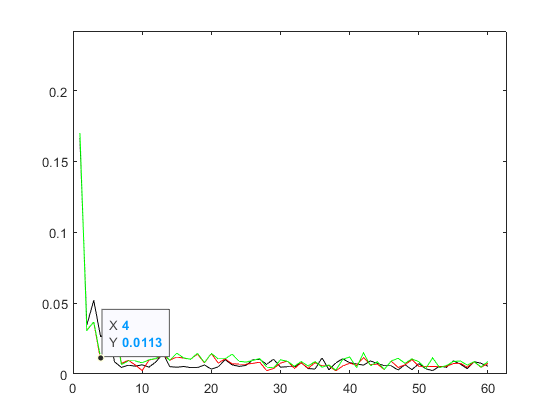


plot(1:60,f,'k');hold on;
plot(1:60,v,'r');hold on;
plot(1:60,w,'g');hold off;


hiddenLayerSize=38;
net = fitnet(hiddenLayerSize);
net.divideParam.trainRatio=60/100;
net.divideParam.valRatio=30/100;
net.divideParam.testRatio=10/100;
[net,tr]=train(net, x1,y);
yTrain=net(x1(:,tr.trainInd));
yTrainTrue=y(:,tr.trainInd);
rmse_train=sqrt(mean((yTrain-yTrainTrue).^2))

rmse_train =     0.0347    0.0368    0.0357    0.0302    0.0240    0.0240    0.0238    0.0238    0.0201    0.0168    0.0147    0.0147    0.0151    0.0157    0.0169    0.0285    0.0302    0.0302    0.0321    0.0334    0.0342    0.0341    0.0343    0.0358    0.0366    0.0369    0.0368    0.0360    0.0354    0.0346    0.0261    0.0347    0.0352    0.0352    0.0359    0.0276    0.0185    0.0185    0.0195    0.0218    0.0282    0.6802    0.6789    0.6789    0.6787    0.6787    0.6784    0.6740    0.6722    0.6717


f=min(rmse_train);
yVal=net(x1(:,tr.valInd));
yValTrue=y(:,tr.valInd);
rmse_val=sqrt(mean((yVal-yValTrue).^2))

rmse_val =     0.0154    0.0185    0.0240    0.0342    0.0350    0.0371    0.0370    0.0352    0.0311    0.0259    0.0275    0.0317    0.0358    0.0361    0.0361    0.0355    0.0345    0.0329    0.0305    0.0213    0.0192    0.0185    0.6830    0.6789    0.6787    0.6787    0.6787    0.6786    0.6770    0.6719    0.6683    0.6512    0.6325    0.6076    0.5678    0.4488    0.2161    0.1082    0.1147    0.1204    0.1336    0.1399    0.1450    0.3192    0.3262    0.3242    0.2719    0.1856    0.1003    0.0805


v=min(rmse_val);
yTest=net(x1(:,tr.testInd));
yTestTrue=y(:,tr.testInd);
rmse_test=sqrt(mean((yTest-yTestTrue).^2))

rmse_test =     0.0357    0.0219    0.0352    0.0281    0.0244    0.0249    0.6754    0.6716    0.1098    0.1831    0.2147    0.1784    0.6802    0.6893    0.6949    0.5286    0.6927    0.6638    0.1879    0.0440    0.0300    0.0313    0.6840    0.6855    0.1426    0.1659    0.1384    0.4998    0.2602    0.2186    0.1915    0.1869    0.3684    0.6258    0.2114    0.1381    0.1490    0.0668    0.0706    0.1292    0.6303    0.0914    0.0749    0.0355    0.0168    0.1086    0.0469    0.0217    0.0305    0.4023


w=min(rmse_test);

f = 0.0081

w = 0.0117